# Fast Cyclic Ankle DF - Individual Analysis.

Authors: F Cenni,[ francesco.cenni@gmail.com](mailto:francesco.cenni@gmail.com)>; P Valadao pvaladao@tuta.io

Starting date: 23 Jan 2020, Last update 30 April 2021:

- Adding condition for choosing subject in the manual_editing section (onset events for stretch reflex);

- Remember: comment/uncomment manual editing section;

- Calculation of SD/mean on every 500ms pre-stretch; 2SD lines are then plot on the 40 individual pre-plots to verify FN and FP ; 

- Indication about 500ms pre-stretch being lower than 5% of the MVC RMS.

- Adding section where the new events are used to find NEW --> just before pre-plots for checking events angles_of_catch_sol2 and latency2 ('update the vars: angle of catch and emgrms_onset' section)

- Delays for EMG wireless are taking into account by cutting the intial part of the signal 

*General Information:*

1) events_emg_sol(mg): all the events detected, by using Staude;

2) events_emg_sol_sel(mg): events selected (only for events happened after ev3);

3) events_emg_sol_sel2, **new condition**** to make sure that the events selected are between ev3 and ev4+latency. An extra condition on events_emg_sol_sel was added to manage some exceptions.

**The var to consider is: events_emg_sol_sel2 and mg**

Use breakpoints after Pre-plots for checking detected events and see new graphs

cond_mvc_sol/mg = 0 ==> trials that will be excluded due to high EMG background cond_mvc_sol/mg = 1 ==> trials that will NOT be excluded, low EMG background

Pipeline for handling false negatives and false positives: Manually corrected events are loaded on line 749, in lines 750-769 the new events are used to calculate the vars of interrest. 

Last updates PV (06/05/21):  1) threshold for valid trials (lines 839/851) changed from 1 to 0.01 deg to avoid eliminating DSRT that happened close to the end of the movement; 2) corrected line 593 to t8/l8 instead of t7/l7 and channel3_d2 to channel4_d2 (MG); notes with all exceptions are listed on the end of the script.

clc
clear all
close all

## Input and Load Data

dataPath = 'C:\Doutorado\Matlab\Paper II\TSRT\TSRT_smr\';
fileName = '5206_pre1_ST.smr';  
data = ImportSMR([dataPath fileName]);
Subject = string(fileName(1:4));
Group = "CP";
Test = "Pre1";
load add_info.mat %  table with latencies + MVC RMS for both muscle
Corrected_filename = '5206_corrected.mat' % correct events_emg_sol/mg_sel2 after visual inspection

Corrected_filename = '5206_corrected.mat'

%raw_file = "5204_raw_events";

## Data Trimming

A few data files are extremely long since data collection was not stopped at the end of the protocol, this section trims the dataset. 5108: 300000:end/ 5119 = 1:150000, 5202 = 1230000:end.

% data(1).imp.adc = data(1).imp.adc(1:130000);
% data(2).imp.adc = data(2).imp.adc(1:130000);
% data(3).imp.adc = data(3).imp.adc(1:2*130000);
% data(4).imp.adc = data(4).imp.adc(1:2*130000);

## Channel_1:Torque data [Nm]

information extracted from the struct **(read struct from smr data)****

f_sample_ch1=1/(data(1).hdr.adc.SampleInterval(1)*data(1).hdr.adc.SampleInterval(2));
variable_name_ch1=data(1).hdr.title;  %name of the variable
unit_ch1=data(1).hdr.adc.Units; %unit channel1
scale_factor_ch1=data(1).hdr.adc.Scale; %scaling factor for channel1
channel1=data(1).imp.adc; %signal 
N_samples_ch1=length(channel1); %number of samples
channel1_scaled=(double(channel1))*scale_factor_ch1; %scaling with double signal
time = N_samples_ch1/f_sample_ch1; %s
fprintf('the measurements took %d s\n',time);

the measurements took 1.408590e+02 s



%filter the data in channel1 (torque)
[b,a]=butter(6,40/(f_sample_ch1/2),'low'); %low-pass filter, order=6, cutoff freq= 40Hz
channel1_scaled_filt = filtfilt(b,a,channel1_scaled); %signal filtered (for outliers is better movmean)
% movemean filter
channel1_scaled_window = movmean(channel1_scaled,80); %where each mean is calculated over a sliding window

## Channel_2 (Angle)

f_sample_ch2 = 1/(data(2).hdr.adc.SampleInterval(1)*data(2).hdr.adc.SampleInterval(2));
% information extracted from the struct
variable_name_ch2=data(2).hdr.title;  
scale_factor_ch2=data(2).hdr.adc.Scale;
unit_ch2=data(2).hdr.adc.Units; %unit channel2
channel2=data(2).imp.adc;  
N_samples_ch2=length(channel2);
channel2_scaled_int=channel2*scale_factor_ch2;
channel2_scaled_d=(double(channel2))*scale_factor_ch2;% double format
% offset detection
starting_value_int=mean(channel2_scaled_int([1:200])); %average from first 200 samples
plantarflex_value_int=starting_value_int+20; %prior knowledge: always 20 deg in plantarflexion
starting_value_d=mean(channel2_scaled_d([1:200])); %average from first 200 samples (double)
plantarflex_value_d=starting_value_d+20; %

## Pre-signal processing (needed because there are some spikes on the angle-signal(int) +/-1 deg)

%indices
i=1;j=1;l=1;m=1;
for c = 1:N_samples_ch2
    if c == N_samples_ch2-200 % to avoid to exceed the N_samples_ch2 array
        break
    end
    if channel2_scaled_int(c) > plantarflex_value_int;
        channel2_scaled_int(c)=plantarflex_value_int;
    end
    if channel2_scaled_int(c) < starting_value_int;
        channel2_scaled_int(c)=starting_value_int;
    end
    if channel2_scaled_int(c) == starting_value_int+1;
        if channel2_scaled_int(c+200) < starting_value_int+2;
            channel2_scaled_int(c)=starting_value_int;
        end
    end
end
channel2_scaled_int = int8(medfilt1(double(channel2_scaled_int),150)); %further cleaning the signal
%detect offset from cleaned signal
starting_value_int=int8(mean(channel2_scaled_int([1:200])));
max_plantar_values_int= max(channel2_scaled_int);
plantarflex_value_int = int8(max_plantar_values_int); %from -real- max value

## Detecting the events from the angle signal

ev1:ankle is started to be plantarflexed / ev2: ankle is in plantarflexion / ev3: ankle is started to be dorsiflexed / ev4:ankle is back to dorsiflexion

for c = 1:N_samples_ch2
    if channel2_scaled_int(c) == starting_value_int+1
        if channel2_scaled_int(c-1) == starting_value_int
            % --ev1-- first event trapezoidal wave form (ankle is started to be plantarflexed)    
            index_ev1(i)=c-1;
            i=i+1;
        end
        if channel2_scaled_int(c+1) == starting_value_int
            % --ev4-- forth event trapez wave form (ankle is now in dorsiflexion)    
            index_ev4(j)=c+1;
            j=j+1;
        end
    end
    if channel2_scaled_int(c) == plantarflex_value_int;
        if channel2_scaled_int(c-1) == plantarflex_value_int-1;
            % --ev2-- second event trapez wave form (ankle is now in plantarflexion)    
            index_ev2(l)=c;
            l=l+1;
        end
        if channel2_scaled_int(c+1) == plantarflex_value_int-1;
            % --ev3-- third event trapez wave form (ankle is started to be dorsiflexed)  
            index_ev3(m)=c;
            m=m+1;
        end
    end
end

## Dorsi/Plantar flexion VELOCITIES [deg/sample]

!!the sequence for the velocities is the same every time!!

for ii = 1:length(index_ev1)
    % it should be always the same
    plantarflex_vel(ii)=20/(index_ev2(ii)-index_ev1(ii));
    % it should be 4 different velocities
    dorsiflex_vel(ii)=20/(index_ev4(ii)-index_ev3(ii));
% velocities classified using 1-2-3-4
    if dorsiflex_vel(ii)<0.06 %thresholds are in deg/sample
       vel_classification(ii)=1;
    elseif dorsiflex_vel(ii)<0.12
       vel_classification(ii)=2;
    elseif dorsiflex_vel(ii)<0.22
       vel_classification(ii)=3;
    else
       vel_classification(ii)=4;    
    end
end

%convert velocity in deg/s
plantarflex_vel_c = plantarflex_vel*f_sample_ch2;
dorsiflex_vel_c = dorsiflex_vel*f_sample_ch2;
%offset for the angle data (channel2_scaled_shifted)
angle_data = channel2_scaled_int - starting_value_int; %int format
angle_data_d = channel2_scaled_d - starting_value_d; %double format
angle_data_d_w = movmean(angle_data_d,10); % N=10 --> sample that is around 10ms; mean calculated over a sliding window

## Channels available for wired system

channel3=data(3).imp.adc; %soleus
channel4=data(4).imp.adc; %MG
channel3_d=double(channel3);%
channel4_d=double(channel4);%

## Channels avalable for wireless system

channel7=data(7).imp.adc; %soleus
channel8=data(8).imp.adc; %MG
channel7_d=double(channel7);%
channel8_d=double(channel8);%

## Pre-plots

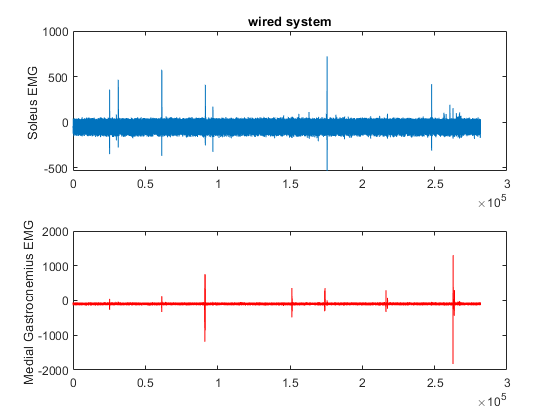

figure(1)
subplot(2,1,1)
plot(channel3)
ylabel('Soleus EMG ')
title('wired system')
hold on
subplot(2,1,2)
plot(channel4,'r')
ylabel('Medial Gastrocnemius EMG ')

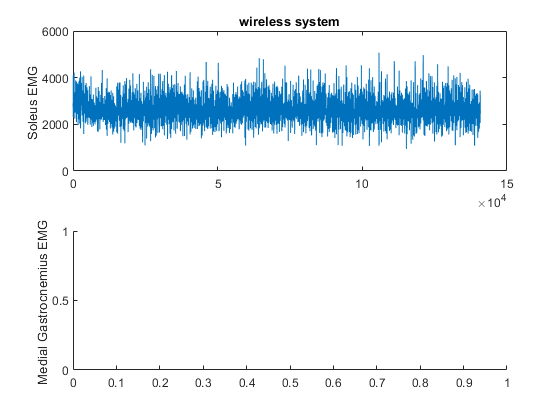

figure(2)
subplot(2,1,1)
plot(channel7)
ylabel('Soleus EMG ')
title('wireless system')
hold on
subplot(2,1,2)
plot(channel8,'r')
ylabel('Medial Gastrocnemius EMG ')

## Condition for selecting the type of EMG channel

filter parameters

%low-pass filter 
fcuthigh=195; %high cut frequency in Hz
[b1,a1]=butter(6,fcuthigh/(4000/2),'low'); %order=6, %fs=4000 
%bandpass
fcutlow=20;   %low cut frequency in Hz
fcuthigh=195;   %high cut frequency in Hz
[b0,a0]=butter(6,[fcutlow,fcuthigh]/(4000/2),'bandpass'); %order=6, %fs=4000 
% ---for envelope--- as in Bar-On 2014
% coefficients for filter; 30 Hz low-pass
[b,a]=butter(6,30/f_sample_ch2*2,'low');
typeEMG = input('Enter type EMG: ','s');

## --> Automatic latency input from table (file name=) add_info.mat

l_vec = strcmp(add_info.Subject,Subject);
[row, ~] = find(l_vec)

row =     19


latency_correction_sol = table2array(add_info(row, 6))

latency_correction_sol =     28


latency_correction_mg = table2array(add_info(row, 7))

latency_correction_mg =     25



%typeEMG=char(n);
switch typeEMG
    case 'wired'

        %%%---------------------channel 3 (WIRED channel SOLEUS)
        variable_name_ch3=data(3).hdr.title;  
        scale_factor_ch3=data(3).hdr.adc.Scale; 
        unit_ch3=data(3).hdr.adc.Units; %unit channel3
        channel3=data(3).imp.adc; 
        N_samples_ch3=length(channel3);
        channel3_d=double(channel3);
        channel3_scaled=channel3_d*scale_factor_ch3;
        freq_ratio = int8(N_samples_ch3./N_samples_ch2);  
        channel3_d2 = resample(channel3_scaled,1,double(freq_ratio)); %channel3_d
        channel3_filt = filtfilt(b0,a0,channel3_d2); %signal filtered
        
        %---onset detection based on the staude function
        % here emg detection is applied
        [t7,l7]=staude_detectemg(channel3_d2); %--> raw signal inserted, otherwise use channel3_filt; add '1' to check graphs
        events_emg_sol=t7{1, 1};  % !all the stretch refflexes (events) detected!
        events_sol_variance=l7{1, 1}; %variance calculated over the signal

        %---select RELEVANT onset events and the corresponding angles of catch
        mm=1;cc=1;
        for ii = 1:length(events_emg_sol)
             if events_emg_sol(ii) > index_ev3(cc);
                 for cc = cc+1:length(index_ev3)+1
                     if cc == length(index_ev3)+1
                        break
                     end
                     if events_emg_sol(ii) > index_ev3(cc);
                         events_emg_sol_sel(cc-1)=0;
                         angles_of_catch_sol(cc-1)=0;
                         angles_of_catch_sol_latency(cc-1)=0;
                     else
                        break
                     end
                 end
                 events_emg_sol_sel(cc-1)=events_emg_sol(ii); % events selected, the ones > ev3
                 events_sol_variance_sel(cc-1)=events_sol_variance(ii); % 
                 angles_of_catch_sol(cc-1)=angle_data_d(events_emg_sol_sel(cc-1));
                 angles_of_catch_sol_latency(cc-1)=angle_data_d(events_emg_sol_sel(cc-1)-int32(latency_correction_sol)); %after latency correction
                 mm=mm+1;
                 if cc == length(index_ev3)+1
                     break
                 end         
             end
        end
        if mm==1 % this means that no events are selected
            events_emg_sol_sel=zeros(1,length(index_ev3));
            events_sol_variance_sel=zeros(1,length(index_ev3));
        end
        %extra condition to refine the events selected using also *index ev4*
        ciao=1; ttsol=1; %ttsol is a flag to check if some events are selected
        for ii = 1:length(events_emg_sol_sel)
            if events_emg_sol_sel(ii) == 0
                ii = ii+1;
            else
                while events_emg_sol_sel(ii) > index_ev4(ciao)+latency_correction_sol
                    if ciao==length(events_emg_sol_sel)
                        break
                    else
                        ciao=ciao+1;
                    end
                end
            
                if events_emg_sol_sel(ii) < index_ev3(ciao)
                    events_emg_sol_sel2(ii) = 0;
                    events_sol_variance_sel2(ii) = 0; %variance
                    angles_of_catch_sol2(ii) = 0;
                    angles_of_catch_sol_latency2(ii) = 0;
                    ttsol=ttsol+1;
                else
                    events_emg_sol_sel2(ii) = events_emg_sol_sel(ii);
                    events_sol_variance_sel2(ii) = events_sol_variance_sel(ii);
                    angles_of_catch_sol2(ii) = angles_of_catch_sol(ii);
                    angles_of_catch_sol_latency2(ii) = angles_of_catch_sol_latency(ii);
                    ttsol=ttsol+1;
                end
            end
        end            
        %%%%%%%
        if ttsol>1
            events_emg_sol_sel2 = [events_emg_sol_sel2, zeros(1,length(index_ev3) - length(events_emg_sol_sel2))];       
            angles_of_catch_sol2 = [angles_of_catch_sol2, zeros(1,length(index_ev3) - length(angles_of_catch_sol2))];
            angles_of_catch_sol_latency2 = [angles_of_catch_sol_latency2, zeros(1,length(index_ev3) - length(angles_of_catch_sol_latency2))];
        else
            events_emg_sol_sel2=zeros(1,length(index_ev3));
            angles_of_catch_sol2=zeros(1,length(index_ev3));
            angles_of_catch_sol_latency2=zeros(1,length(index_ev3));
        end
        %RMS envelope from EMG signal (as Bar-On 2014)
        emgrms_sol = sqrt( abs(filtfilt(b,a,channel3_d2.^2))+1E-14);
        %(rectfied emg signal)
        emgrms2_sol = sqrt(abs(channel3_filt.^2)+1E-14); %soleus
        % rms (from sqrt and ^2) of a sliding window (200ms),
        %using filtered emg signal, check example here https://it.mathworks.com/matlabcentral/answers/310418-how-do-i-calculate-the-rms-of-every-5-values
        emgrms_sol_mw_200_new = sqrt(movmean(channel3_filt.^2,200));

        %calculate RMS at resting periods, last 500ms before stretch (ALL) 
        for i = 1:length(index_ev2)
            %%from envelope 
            %emgrms_interval_plantar_sol_f=emgrms_sol((index_ev3(i)-500):index_ev3(i)); %last 500ms before stretch
            %avgs_emgrms_interval_plantar_sol_f(i)=mean(emgrms_interval_plantar_sol_f);            
            %from emg signal
            %emgrms_interval_plantar_sol=emgrms2_sol((index_ev3(i)-500):index_ev3(i)); %last 500ms before stretch
            %avgs_emgrms_interval_plantar_sol(i)=mean(emgrms_interval_plantar_sol);
            %maxs_emgrms_interval_plantar_sol_mw(i) = max(emgrms_sol_mw_200_new((index_ev3(i)-500):index_ev3(i))); %max among RMSs
            %
            % sol signal extracted for the relevant section
            emg_sol_cut = channel3_filt((index_ev3(i)-500):index_ev3(i));
            % M = movmean(A,3,'Endpoints','discard') ONLY full window average
            maxs_emgrms_interval_plantar_sol_mw(i) = max(sqrt(movmean(emg_sol_cut.^2,200,'Endpoints','discard'))); %200 win length
            
            % mean and std on the resting periods
            mean_emg_interval_plantar_sol1(i)=mean(channel3_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
            std_emg_interval_plantar_sol1(i)=std(channel3_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
        end

        %calculate RMS before (ALL) the stretches
        t_interv_dorsi_starting=index_ev1(1);
        %NEW: !correct version!
        emgrms_interval_dorsi_starting_sol_new=rms(channel3_filt(int16(t_interv_dorsi_starting)-1500:int16(t_interv_dorsi_starting)-500)); %1s
   
        if ttsol>1 %%otherwise no events selected!
            %calculate RMS at EMG onset (+100/200ms)
            delay_onset = 50; %!!insert here the delay    
            for i = 1:length(index_ev3)
                if events_emg_sol_sel2(i) > 1 % remove events without onset        
                    %emgrms_onset_sol=emgrms2_sol(events_emg_sol_sel2(i):(events_emg_sol_sel2(i)+delay_onset)); %
                    %avgs_emgrms_onset_sol(i)=mean(emgrms_onset_sol);
                    %NEW: !correct version!
                    emgrms_onset_sol_new(i)=rms(channel3_filt(events_emg_sol_sel2(i):(events_emg_sol_sel2(i)+delay_onset))); %
                else
                    %avgs_emgrms_onset_sol(i)=0;
                    emgrms_onset_sol_new(i)=0;
                end
            end
        else
            %avgs_emgrms_onset_sol=zeros(1,length(index_ev3));
            emgrms_onset_sol_new=zeros(1,length(index_ev3));
        end      
        
        
        %--------------------------------------------------------------------------

        %%%---------------------channel 4 (wired channel MG)
        variable_name_ch4=data(4).hdr.title;  
        scale_factor_ch4=data(4).hdr.adc.Scale;
        unit_ch4=data(4).hdr.adc.Units; %unit channel4
        channel4=data(4).imp.adc;  
        N_samples_ch4=length(channel4);
        channel4_d=double(channel4);
        channel4_scaled=channel4_d*scale_factor_ch4;
        freq_ratio = int8(N_samples_ch4/N_samples_ch2);
        channel4_d2 = resample(channel4_scaled,1,double(freq_ratio)); %channel4_d
        channel4_filt = filtfilt(b0,a0,channel4_d2); %signal filtered
        
        %---onset detection based on the staude function
        % here emg detection is applied
        [t8,l8]=staude_detectemg(channel4_d2);%channel4_d
        events_emg_mg=t8{1, 1};
        events_variance_mg=l8{1, 1}; %variance calculated over the signal
       
        %---select RELEVANT onset events and the corresponding angle of catch
        mm=1;cc=1; 
        for ii = 1:length(events_emg_mg)
             if events_emg_mg(ii) > index_ev3(cc);
                 for cc = cc+1:length(index_ev3)+1
                     if cc == length(index_ev3)+1 %
                        break
                     end
                     if events_emg_mg(ii) > index_ev3(cc);
                         events_emg_mg_sel(cc-1)=0;
                         events_variance_mg_sel(cc-1)=0;
                         angles_of_catch_mg(cc-1)=0;
                         angles_of_catch_mg_latency(cc-1)=0;
                     else
                        break
                     end
                 end
                 events_emg_mg_sel(cc-1)=events_emg_mg(ii);
                 events_variance_mg_sel(cc-1)=events_variance_mg(ii); %
                 angles_of_catch_mg(cc-1)=angle_data_d(events_emg_mg_sel(cc-1));
                 angles_of_catch_mg_latency(cc-1)=angle_data_d(events_emg_mg_sel(cc-1)-int32(latency_correction_mg)); %after latency correction
                 mm=mm+1;                
                 if cc == length(index_ev3)+1
                     break
                 end         
             end
        end
        if mm==1 % this means that no events are selected
            events_emg_mg_sel=zeros(1,length(index_ev3));
            events_variance_mg_sel=zeros(1,length(index_ev3));
        end
        %extra condition to refine the events selected using also *index ev4*
        ciao=1; ttmg=1; %tt is a flag to check if some events are selected
        for ii = 1:length(events_emg_mg_sel)
            if events_emg_mg_sel(ii) == 0
                ii = ii+1;
            else
                while events_emg_mg_sel(ii) > index_ev4(ciao)+latency_correction_mg
                    if ciao==length(events_emg_sol_sel)
                        break
                    else
                        ciao=ciao+1;
                    end
                end
            
                if events_emg_mg_sel(ii) < index_ev3(ciao)
                    events_emg_mg_sel2(ii) = 0;
                    events_variance_mg_sel2(ii) = 0; %variance
                    angles_of_catch_mg2(ii) = 0;
                    angles_of_catch_mg_latency2(ii) = 0;
                    ttmg = ttmg+1;
                else
                    events_emg_mg_sel2(ii) = events_emg_mg_sel(ii);
                    events_variance_mg_sel2(ii) = events_variance_mg_sel(ii);
                    angles_of_catch_mg2(ii) = angles_of_catch_mg(ii);
                    angles_of_catch_mg_latency2(ii) = angles_of_catch_mg_latency(ii);
                    ttmg = ttmg+1;
                end
            end
        end
        
        if ttmg>1
            events_emg_mg_sel2 = [events_emg_mg_sel2, zeros(1,length(index_ev3) - length(events_emg_mg_sel2))];
            events_variance_mg_sel2 = [events_variance_mg_sel2, zeros(1,length(index_ev3) - length(events_emg_mg_sel2))];
            angles_of_catch_mg2 = [angles_of_catch_mg2, zeros(1,length(index_ev3) - length(angles_of_catch_mg2))];
            angles_of_catch_mg_latency2 = [angles_of_catch_mg_latency2, zeros(1,length(index_ev3) - length(angles_of_catch_mg_latency2))];
         else
            events_emg_mg_sel2=zeros(1,length(index_ev3));
            events_variance_mg_sel2=zeros(1,length(index_ev3));
            angles_of_catch_mg2=zeros(1,length(index_ev3));
            angles_of_catch_mg_latency2=zeros(1,length(index_ev3));
        end
        %RMS envelope from EMG signal (as Bar-On 2014)
        emgrms_mg = sqrt( abs(filtfilt(b,a,channel4_d2.^2))+1E-14);
        %(rectfied emg signal)
        emgrms2_mg = sqrt(abs(channel4_filt.^2)+1E-14);
        %NEW: rms (from sqrt and ^2) of a sliding window (200ms),
        %using filtered emg signal, check example here https://it.mathworks.com/matlabcentral/answers/310418-how-do-i-calculate-the-rms-of-every-5-values
        emgrms_mg_mw_200_new = sqrt(movmean(channel4_filt.^2,200));

        %calculate RMS at resting periods, last 500ms before stretch
        for i = 1:length(index_ev2)
            % mg signal extracted for the relevant section
            emg_mg_cut = channel4_filt((index_ev3(i)-500):index_ev3(i));
            % M = movmean(A,3,'Endpoints','discard') ONLY full window average
            maxs_emgrms_interval_plantar_mg_mw(i) = max(sqrt(movmean(emg_mg_cut.^2,200,'Endpoints','discard')));
            % mean and std on the resting periods
            mean_emg_interval_plantar_mg1(i)=mean(channel4_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
            std_emg_interval_plantar_mg1(i)=std(channel4_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
        end

        %calculate RMS before the stretches     
        %NEW: !correct version!
        emgrms_interval_dorsi_starting_mg_new=rms(channel4_filt(int16(t_interv_dorsi_starting)-1500:int16(t_interv_dorsi_starting)-500)); %1s
        
        if ttmg>1 %%otherwise no events selected!
            %calculate RMS at EMG onset (+100/200ms)
            delay_onset = 50; %!!insert here the delay   
            for i = 1:length(index_ev3)
                if events_emg_mg_sel2(i) > 1 % remove events without onset        
                    %NEW: correct version
                    emgrms_onset_mg_new(i)=rms(channel4_filt(events_emg_mg_sel2(i):(events_emg_mg_sel2(i)+delay_onset))); %
                else
                    emgrms_onset_mg_new(i)=0;
                end
            end
        else
            emgrms_onset_mg_new=zeros(1,length(index_ev3));
        end
        % channel5 TA
        variable_name_ch5=data(5).hdr.title;  
        scale_factor_ch5=data(5).hdr.adc.Scale;
        unit_ch5=data(5).hdr.adc.Units; %unit channel5
        channel5=data(5).imp.adc;  
        N_samples_ch5=length(channel5);
        channel5_d=double(channel5);
        channel5_scaled=channel5_d*scale_factor_ch5;
        freq_ratio = int8(N_samples_ch5/N_samples_ch2);
        channel5_d2 = resample(channel5_scaled,1,double(freq_ratio)); %channel5_d
        %onset detection based on the staude function
        channel5_filt = filtfilt(b0,a0,channel5_d2); %signal filtered
    
    case 'wireless'
        
        %%%---------------------channel 7 (wireless channel SOLEUS)
        t_delay_ch7 = 200; %ms !!!-->the emg data have a constant delay of 200ms with respect angle data
        variable_name_ch7=data(7).hdr.title;  
        scale_factor_ch7=data(7).hdr.adc.Scale; %this seems not needed
        unit_ch7=data(7).hdr.adc.Units; %unit channel4
        channel7=data(7).imp.adc((t_delay_ch7+1):end); %cutting off the first 200ms
        channel7(end+1:end+t_delay_ch7)= 0; %filling with zeros to preserve vector length
        N_samples_ch7=length(channel7);
        channel7_d=double(channel7);
        channel7_scaled=channel7_d*scale_factor_ch7;
        freq_ratio = int8(N_samples_ch7./N_samples_ch2);  %% !!check var
        channel3_d2 = resample(channel7_scaled,1,double(freq_ratio));

        %---onset detection based on the staude function
        channel3_filt = filtfilt(b0,a0,channel3_d2); %signal filtered
        [t7,l7]=staude_detectemg(channel3_d2);
        events_emg_sol=t7{1, 1};
        events_variance=l7{1, 1}; %variance calculated on the signal

        %---select RELEVANT onset events and the corresponding angles of catch
        mm=1;cc=1;
        %if cc <= length(index_ev3)
        for ii = 1:length(events_emg_sol)
             if events_emg_sol(ii) > index_ev3(cc)
                 for cc = cc+1:length(index_ev3)+1
                     if cc == length(index_ev3)+1
                        break
                     end
                     if events_emg_sol(ii) > index_ev3(cc)
                         events_emg_sol_sel(cc-1)=0;
                         angles_of_catch_sol(cc-1)=0;
                         angles_of_catch_sol_latency(cc-1)=0;
                     else
                        break
                     end
                 end
                 events_emg_sol_sel(cc-1)=events_emg_sol(ii);
                 events_variance_sel(cc-1)=events_variance(ii); % 
                 angles_of_catch_sol(cc-1)=angle_data_d(events_emg_sol_sel(cc-1));
                 angles_of_catch_sol_latency(cc-1)=angle_data_d(events_emg_sol_sel(cc-1)-int32(latency_correction_sol)); %after latency correction
                 mm=mm+1;
                 
                 if cc == length(index_ev3)+1
                     break
                 end         
             end
        end
		if mm==1 %this mean that no events are selected
            events_emg_sol_sel=zeros(1,length(index_ev3));
            events_variance_sel=zeros(1,length(index_ev3));
        end
        %extra condition to refine the events selected using also index ev4
        ciao=1; ttsol=1; %ttsol is a flag to check if some events are selected
        for ii = 1:length(events_emg_sol_sel)
            if events_emg_sol_sel(ii) == 0
                ii = ii+1;
            else
                while events_emg_sol_sel(ii) > index_ev4(ciao)+latency_correction_sol
                    if ciao==length(events_emg_sol_sel)
                        break
                    else
                        ciao=ciao+1;
                    end
                end
            
                if events_emg_sol_sel(ii) < index_ev3(ciao) 
                    events_emg_sol_sel2(ii) = 0;
                    events_variance_sel2(ii) = 0; %variance
                    angles_of_catch_sol2(ii) = 0;
                    angles_of_catch_sol_latency2(ii) = 0;
					ttsol=ttsol+1;
                else
                    events_emg_sol_sel2(ii) = events_emg_sol_sel(ii);
                    events_variance_sel2(ii) = events_variance_sel(ii);
                    angles_of_catch_sol2(ii) = angles_of_catch_sol(ii);
                    angles_of_catch_sol_latency2(ii) = angles_of_catch_sol_latency(ii);
					ttsol=ttsol+1;
				end
            end
        end
        %
		if ttsol>1
			events_emg_sol_sel2 = [events_emg_sol_sel2, zeros(1,length(index_ev3) - length(events_emg_sol_sel2))];
			angles_of_catch_sol2 = [angles_of_catch_sol2, zeros(1,length(index_ev3) - length(angles_of_catch_sol2))];
			angles_of_catch_sol_latency2 = [angles_of_catch_sol_latency2, zeros(1,length(index_ev3) - length(angles_of_catch_sol_latency2))];
		else
		    events_emg_sol_sel2=zeros(1,length(index_ev3));
            angles_of_catch_sol2=zeros(1,length(index_ev3));
            angles_of_catch_sol_latency2=zeros(1,length(index_ev3));
        end
		
        % coefficients for filter; 30 Hz low-pass
        [b,a]=butter(6,30/f_sample_ch2*2,'low');
        %RMS envelope from EMG signal (as Bar-On 2014)
        emgrms_sol = sqrt( abs(filtfilt(b,a,channel3_d2.^2))+1E-14);
        %(rectfied emg signal)
        emgrms2_sol = sqrt(abs(channel3_filt.^2)+1E-14);
        %NEW 2/3/21: rms (from sqrt and ^2) of a sliding window (200ms),
        %using filtered emg signal, check example here https://it.mathworks.com/matlabcentral/answers/310418-how-do-i-calculate-the-rms-of-every-5-values
        emgrms_sol_mw_200_new = sqrt(movmean(channel3_filt.^2,200));

        %calculate RMS at resting periods
        for i = 1:length(index_ev2)
            %NEW !CORRECT version!
            % sol signal extracted for the relevant section
            emg_sol_cut = channel3_filt((index_ev3(i)-500):index_ev3(i));
            % M = movmean(A,3,'Endpoints','discard') ONLY full window average
            maxs_emgrms_interval_plantar_sol_mw(i) = max(sqrt(movmean(emg_sol_cut.^2,200,'Endpoints','discard')));
            % mean and std on the resting periods
            mean_emg_interval_plantar_sol1(i)=mean(channel3_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
            std_emg_interval_plantar_sol1(i)=std(channel3_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
        end

        %calculate RMS before the stretches
        t_interv_dorsi_starting=index_ev1(1);
        %NEW 2/3/21: !correct version!
        emgrms_interval_dorsi_starting_sol_new=rms(channel3_filt(int16(t_interv_dorsi_starting)-1500:int16(t_interv_dorsi_starting)-500)); %1s

        if ttsol>1 %%otherwise no events selected!
			%calculate RMS at EMG onset (+100/200ms)
			delay_onset = 50; %!!insert here the delay    
			for i = 1:length(index_ev3)
				if events_emg_sol_sel2(i) > 1 % remove events without onset        
                    %NEW 2/3/21: !correct version!
                    emgrms_onset_sol_new(i)=rms(channel3_filt(events_emg_sol_sel2(i):(events_emg_sol_sel2(i)+delay_onset))); %
				else
                    emgrms_onset_sol_new(i)=0;
				end
			end
		else
            emgrms_onset_sol_new=zeros(1,length(index_ev3));
        end
        
        %%%-----------------------------channel 8 (wireless channel Medial gastrocnemius)
        t_delay_ch8 = 200; %ms !!!-->the emg data have a constant delay of 200ms with respect angle data
        variable_name_ch8=data(8).hdr.title;  
        scale_factor_ch8=data(8).hdr.adc.Scale; %this seems not needed
        unit_ch8=data(8).hdr.adc.Units; %unit channel4
        channel8=data(8).imp.adc((t_delay_ch8+1):end); %cutting off the first 200ms
        channel8(end+1:end+t_delay_ch8)= 0; %filling with zeros to preserve vector length
        N_samples_ch8=length(channel8);
        channel8_d=double(channel8);
        channel8_scaled=channel8_d*scale_factor_ch8;
        freq_ratio = int8(N_samples_ch8./N_samples_ch2);  %% 
        channel4_d2 = resample(channel8_scaled,1,double(freq_ratio));       
        
        %---onset detection based on the staude function
        channel4_filt = filtfilt(b0,a0,channel4_d2); %signal filtered
        [t8,l8]=staude_detectemg(channel4_d2);
        events_emg_mg=t8{1, 1};
        events_variance_mg=l8{1, 1}; %variance calculated on the signal

        %---select RELEVANT onset events and the corresponding angles of catch
        mm=1;cc=1;
        for ii = 1:length(events_emg_mg)
            if events_emg_mg(ii) > index_ev3(cc);
                 for cc = cc+1:length(index_ev3)+1
                     if cc == length(index_ev3)+1
                        break
                     end
                     if events_emg_mg(ii) > index_ev3(cc);
                         events_emg_mg_sel(cc-1)=0;
                         angles_of_catch_mg(cc-1)=0;
                         angles_of_catch_mg_latency(cc-1)=0;
                     else
                        break
                     end
                end
                 events_emg_mg_sel(cc-1)=events_emg_mg(ii);
                 events_variance_mg_sel(cc-1)=events_variance_mg(ii); %
                 angles_of_catch_mg(cc-1)=angle_data_d(events_emg_mg_sel(cc-1));
                 angles_of_catch_mg_latency(cc-1)=angle_data_d(events_emg_mg_sel(cc-1)-int32(latency_correction_mg)); %after latency correction
                 mm=mm+1;
                 %
                 if cc == length(index_ev3)+1
                     break
                end         
            end
        end
		if mm==1 % this means that no events are selected
            events_emg_mg_sel=zeros(1,length(index_ev3));
            events_variance_mg_sel=zeros(1,length(index_ev3));
        end
        %new condition
        ciao=1; ttmg=1; %tt is a flag to check if some events are selected
        for ii = 1:length(events_emg_mg_sel)
            if events_emg_mg_sel(ii) == 0
                ii = ii+1;
            else
                while events_emg_mg_sel(ii) > index_ev4(ciao)+latency_correction_mg
                    if ciao==length(events_emg_mg_sel)
                        break
                    else
                        ciao=ciao+1;
                    end
                end
            
                if events_emg_mg_sel(ii) < index_ev3(ciao)
                    events_emg_mg_sel2(ii) = 0;
                    events_variance_mg_sel2(ii) = 0; %variance
                    angles_of_catch_mg2(ii) = 0;
                    angles_of_catch_mg_latency2(ii) = 0;
					ttmg = ttmg+1;
                else
                    events_emg_mg_sel2(ii) = events_emg_mg_sel(ii);
                    events_variance_mg_sel2(ii) = events_variance_mg_sel(ii);
                    angles_of_catch_mg2(ii) = angles_of_catch_mg(ii);
                    angles_of_catch_mg_latency2(ii) = angles_of_catch_mg_latency(ii);
					ttmg = ttmg+1;
                end
            end
        end
        
		if ttmg>1
			events_emg_mg_sel2 = [events_emg_mg_sel2, zeros(1,length(index_ev3) - length(events_emg_mg_sel2))];
            events_variance_mg_sel2 = [events_variance_mg_sel2, zeros(1,length(index_ev3) - length(events_emg_mg_sel2))];
			angles_of_catch_mg2 = [angles_of_catch_mg2, zeros(1,length(index_ev3) - length(angles_of_catch_mg2))];
			angles_of_catch_mg_latency2 = [angles_of_catch_mg_latency2, zeros(1,length(index_ev3) - length(angles_of_catch_mg_latency2))];
		else
            events_emg_mg_sel2=zeros(1,length(index_ev3));
            events_variance_mg_sel2=zeros(1,length(index_ev3));
            angles_of_catch_mg2=zeros(1,length(index_ev3));
            angles_of_catch_mg_latency2=zeros(1,length(index_ev3));
        end
		%RMS envelope from EMG signal (as Bar-On 2014)
        emgrms_mg = sqrt(abs(filtfilt(b,a,channel4_d2.^2))+1E-14);
        %(rectfied emg signal)
        emgrms2_mg = sqrt(abs(channel4_filt.^2)+1E-14);
        %NEW 2/3/21: rms (from sqrt and ^2) of a sliding window (200ms),
        %using filtered emg signal, check example here https://it.mathworks.com/matlabcentral/answers/310418-how-do-i-calculate-the-rms-of-every-5-values
        emgrms_mg_mw_200_new = sqrt(movmean(channel4_filt.^2,200));

        %calculate RMS at resting periods
        for i = 1:length(index_ev2)
            %NEW
            % mg signal extracted for the relevant section
            emg_mg_cut = channel3_filt((index_ev3(i)-500):index_ev3(i));
            % M = movmean(A,3,'Endpoints','discard') ONLY full window average
            maxs_emgrms_interval_plantar_mg_mw(i) = max(sqrt(movmean(emg_mg_cut.^2,200,'Endpoints','discard')));
            % mean and std on the resting periods
            mean_emg_interval_plantar_mg1(i)=mean(channel4_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
            std_emg_interval_plantar_mg1(i)=std(channel4_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
        end

        %%calculate RMS before the stretches
        t_interv_dorsi_starting=index_ev1(1);
        %NEW 2/3/21: !correct version!
        emgrms_interval_dorsi_starting_mg_new=rms(channel4_filt(int16(t_interv_dorsi_starting)-1500:int16(t_interv_dorsi_starting)-500)); %1s
        
        if ttmg>1 %%otherwise no events selected!
			%calculate RMS at EMG onset (+100/200ms)
			delay_onset = 50; %!!insert here the delay    
			for i = 1:length(index_ev3)
				if events_emg_mg_sel2(i) > 1 % remove events without onset        
                    %NEW 2/3/21: correct version
                    emgrms_onset_mg_new(i)=rms(channel4_filt(events_emg_mg_sel2(i):(events_emg_mg_sel2(i)+delay_onset))); %
				else
                    emgrms_onset_mg_new(i)=0;
				end
			end
		else
            emgrms_onset_mg_new=zeros(1,length(index_ev3));
        end	
        
        %%%--------------------------channel 9 (wireless channel TA)
        t_delay_ch5 = 200; %ms !!!-->the emg data have a constant delay of 200ms with respect angle data
        variable_name_ch5=data(9).hdr.title;  
        scale_factor_ch5=data(9).hdr.adc.Scale; %this seems not needed
        unit_ch5=data(9).hdr.adc.Units; 
        channel5=data(9).imp.adc; 
        N_samples_ch5=length(channel5);
        channel5_d=double(channel5);
        channel5_scaled=channel5_d*scale_factor_ch5;
        freq_ratio = int8(N_samples_ch5./N_samples_ch2);  %% 
        channel5_d2 = resample(channel5_scaled,1,double(freq_ratio));
        
end        
close all

## Condition related with MVC

%import data from add_info
emgrms_mvc_sol = table2array(add_info(row, 4))

emgrms_mvc_sol =         0.0703493071311538


emgrms_mvc_mg = table2array(add_info(row, 5))

emgrms_mvc_mg =          0.298273153497487


%
num_trials_sol_excluded=0; num_trials_mg_excluded=0; 
for i = 1:length(index_ev1)
    if maxs_emgrms_interval_plantar_sol_mw(i) > emgrms_mvc_sol*0.05
        cond_mvc_sol(i) = 0; % trials that will be excluded due to high EMG background
        num_trials_sol_excluded = num_trials_sol_excluded+1;
    else
        cond_mvc_sol(i) = 1; % trials with low EMG background
    end
    if maxs_emgrms_interval_plantar_mg_mw(i) > emgrms_mvc_mg*0.05
        cond_mvc_mg(i) = 0; % trials that will be excluded due to high EMG background
        num_trials_mg_excluded = num_trials_mg_excluded+1;        
    else
        cond_mvc_mg(i) = 1; % trials with low EMG background
    end           
end
fprintf('the total number of trials excluded for SOL is %.1i \n',num_trials_sol_excluded);

the total number of trials excluded for SOL is 0 


fprintf('the total number of trials excluded for MG is %.1i \n',num_trials_mg_excluded);

the total number of trials excluded for MG is 1 


## Save raw event list for both muscles - Comment when not needed!

%save(raw_file, 'events_emg_sol_sel2', 'events_emg_mg_sel2')

## Load correct events after the FNFP handler is used - Comment when not needed!

load (Corrected_filename);

## update the vars: angle of catch and emgrms_onset

angles_of_catch_sol2(1:end) = 0;
angles_of_catch_sol_latency2(1:end) = 0;
emgrms_onset_sol_new(1:end) = 0;
angles_of_catch_mg2(1:end) = 0;
angles_of_catch_mg_latency2(1:end) = 0;
emgrms_onset_mg_new(1:end) = 0;
for jj = 1:length(events_emg_sol_sel2)
    if events_emg_sol_sel2(jj) ~= 0 && cond_mvc_sol(jj) == 1
        %SOL
        angles_of_catch_sol2(jj)=angle_data_d(events_emg_sol_sel2(jj));
        angles_of_catch_sol_latency2(jj)=angle_data_d(events_emg_sol_sel2(jj)-int32(latency_correction_sol)); %after latency correction
        emgrms_onset_sol_new(jj)=rms(channel3_filt(events_emg_sol_sel2(jj):(events_emg_sol_sel2(jj)+delay_onset)));
    end
    if events_emg_mg_sel2(jj) ~= 0 && cond_mvc_mg(jj) == 1
        %MG
        angles_of_catch_mg2(jj)=angle_data_d(events_emg_mg_sel2(jj));
        angles_of_catch_mg_latency2(jj)=angle_data_d(events_emg_mg_sel2(jj)-int32(latency_correction_mg)); %after latency correction
        emgrms_onset_mg_new(jj)=rms(channel3_filt(events_emg_mg_sel2(jj):(events_emg_mg_sel2(jj)+delay_onset)));
    end
end

## Pre-plots for checking detected events

Stretch number 1. Velocity = 55.

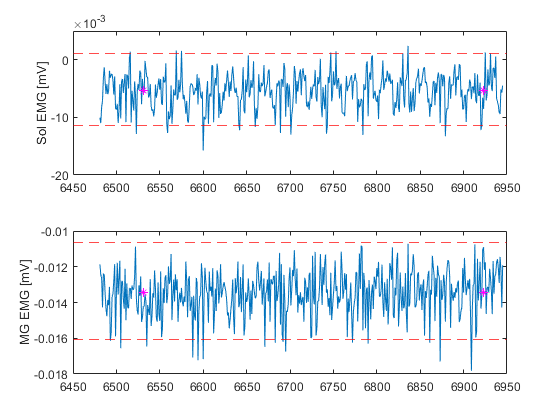

Stretch number 2. Velocity = 110.

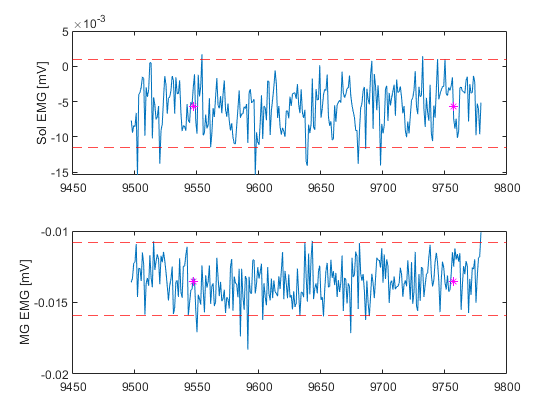

Stretch number 3. Velocity = 213.

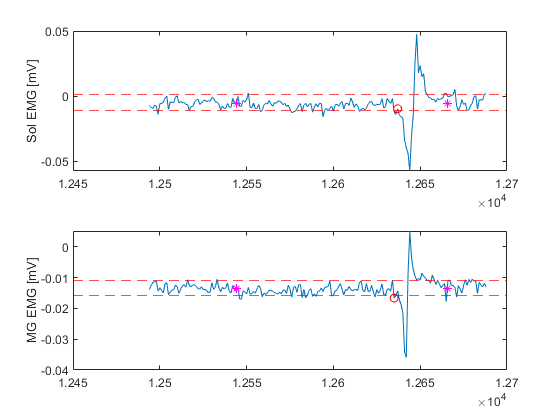

Stretch number 4. Velocity = 299.

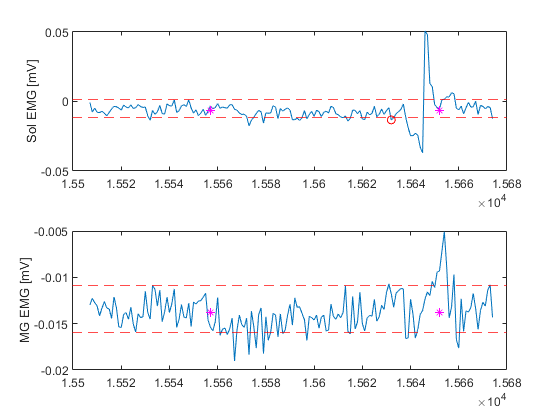

Stretch number 5. Velocity = 110.

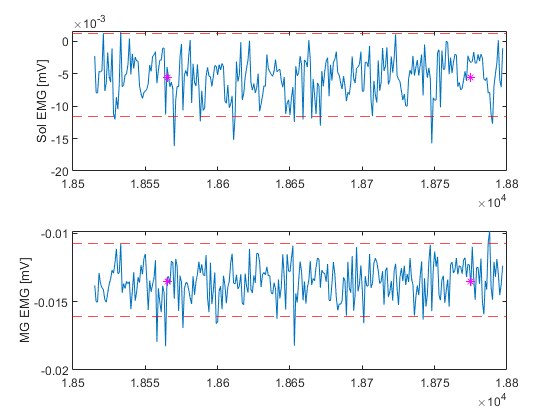

Stretch number 6. Velocity = 55.

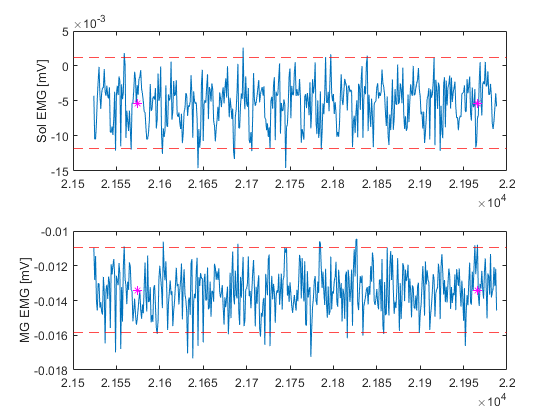

Stretch number 7. Velocity = 294.

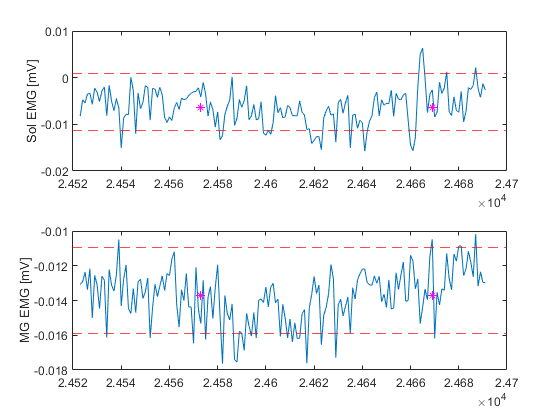

Stretch number 8. Velocity = 211.

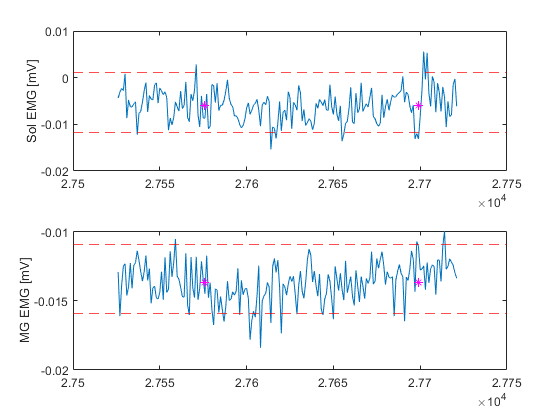

Stretch number 9. Velocity = 294.

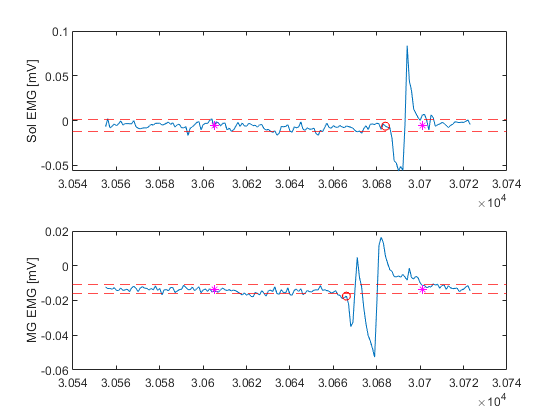

Stretch number 10. Velocity = 213.

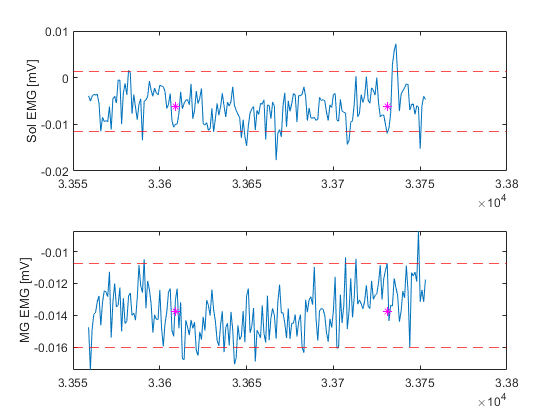

Stretch number 11. Velocity = 110.

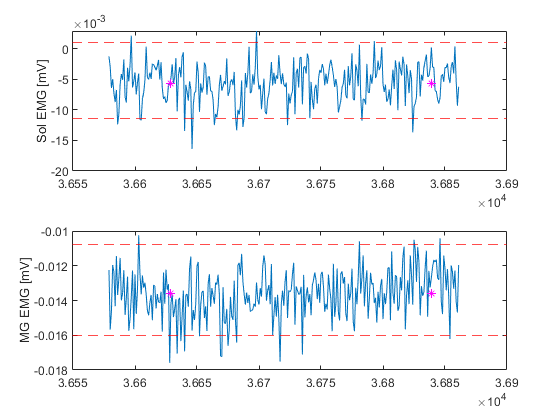

Stretch number 12. Velocity = 55.

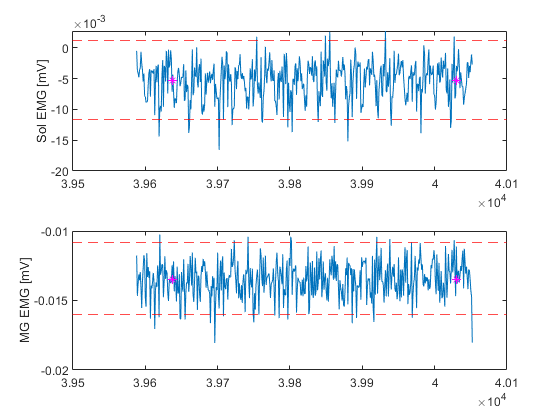

Stretch number 13. Velocity = 211.

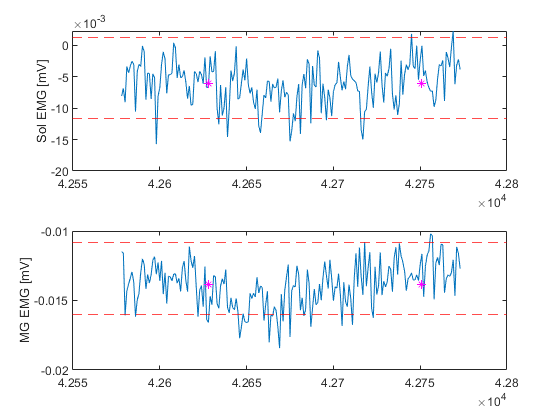

Stretch number 14. Velocity = 294.

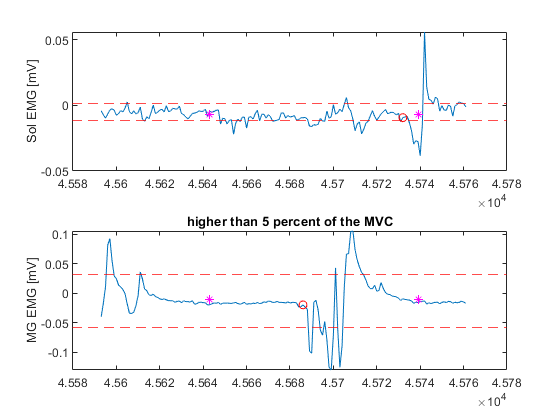

Stretch number 15. Velocity = 55.

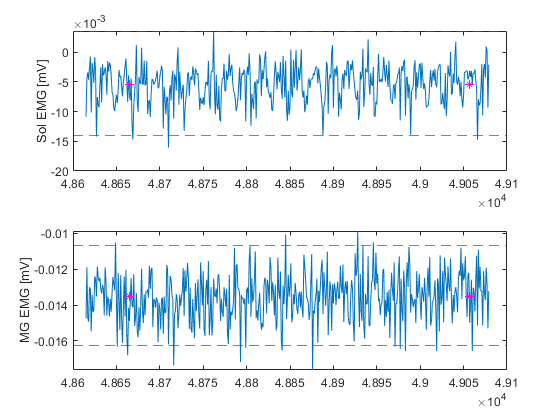

Stretch number 16. Velocity = 110.

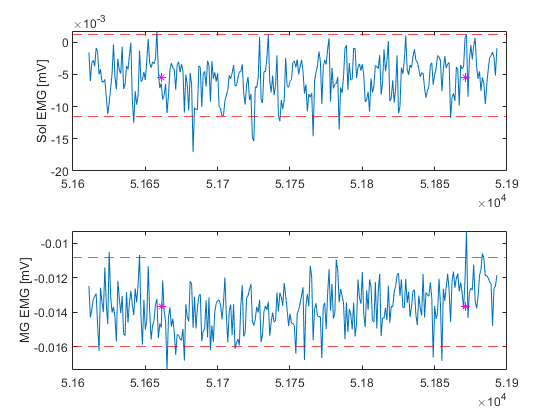

Stretch number 17. Velocity = 299.

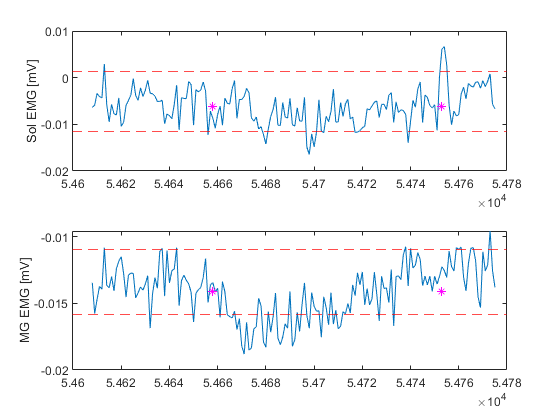

Stretch number 18. Velocity = 211.

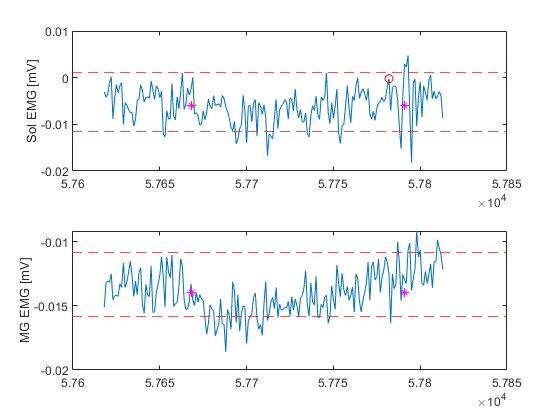

Stretch number 19. Velocity = 110.

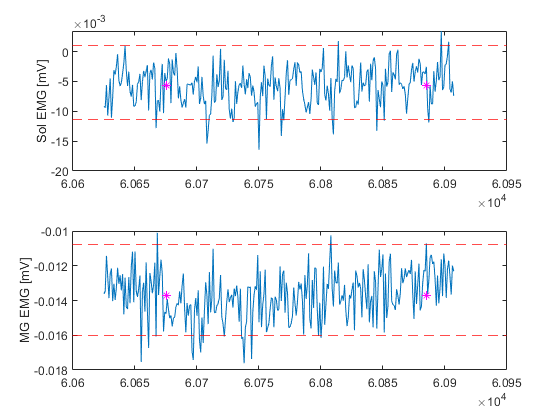

Stretch number 20. Velocity = 55.

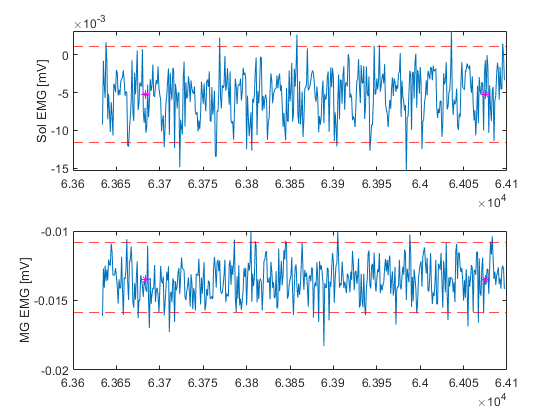

Stretch number 21. Velocity = 110.

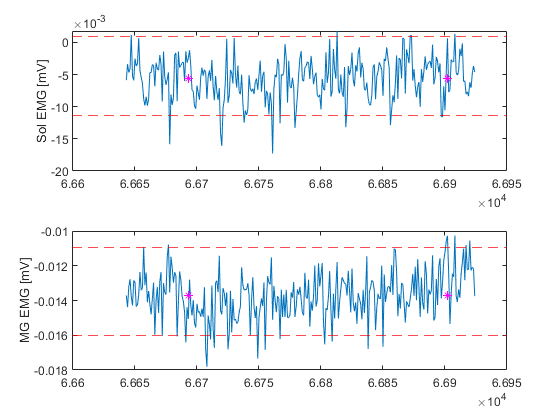

Stretch number 22. Velocity = 55.

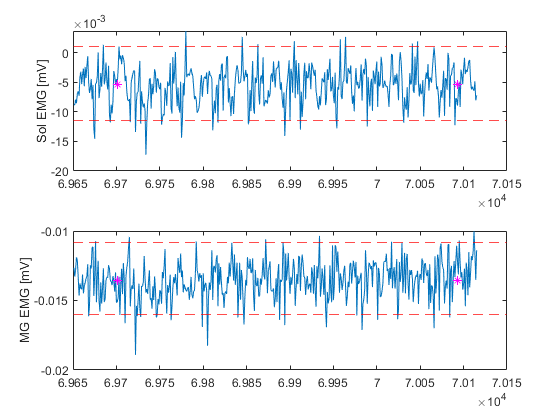

Stretch number 23. Velocity = 294.

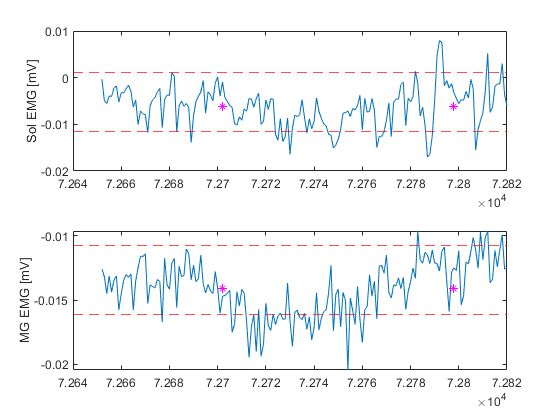

Stretch number 24. Velocity = 213.

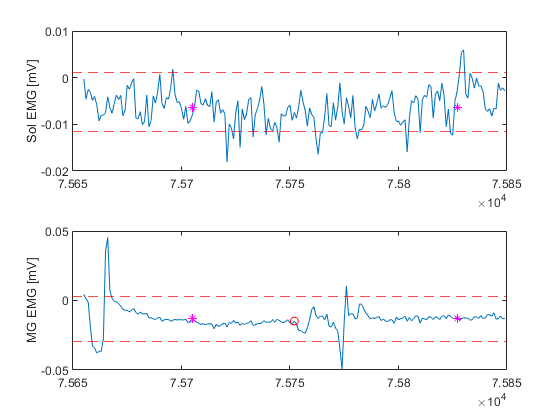

Stretch number 25. Velocity = 55.

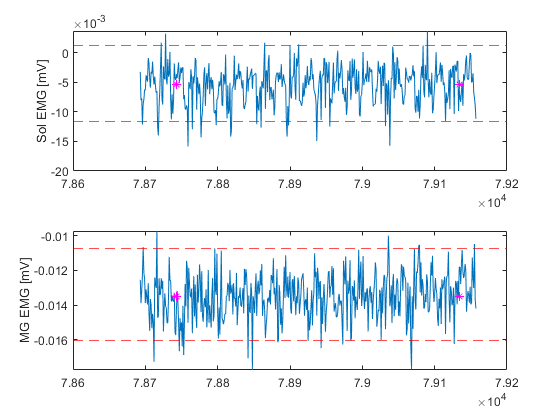

Stretch number 26. Velocity = 110.

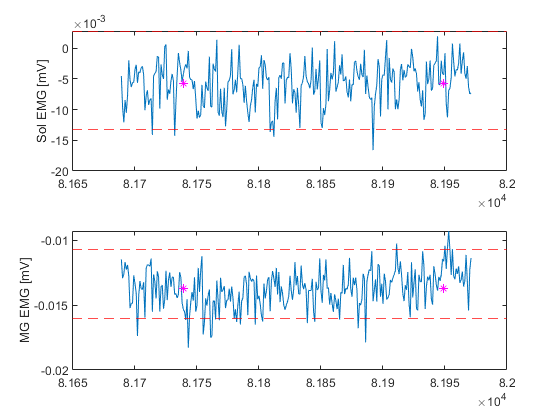

Stretch number 27. Velocity = 213.

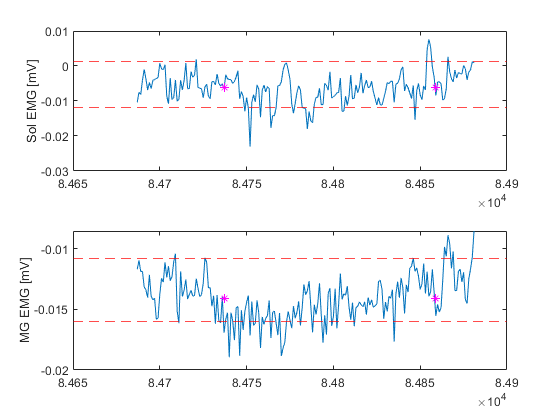

Stretch number 28. Velocity = 299.

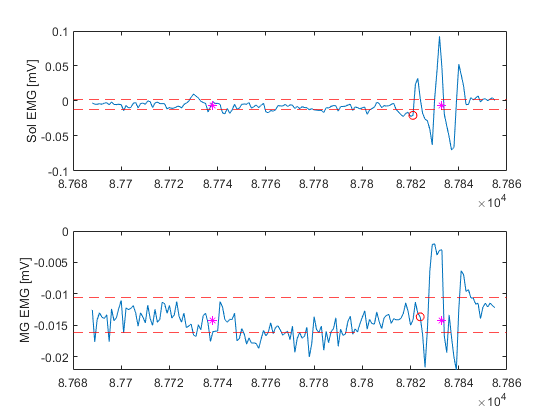

Stretch number 29. Velocity = 213.

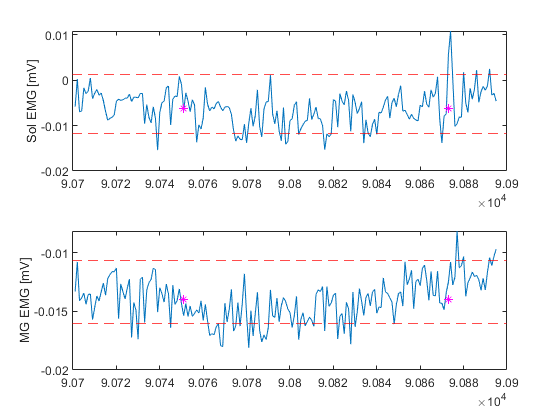

Stretch number 30. Velocity = 294.

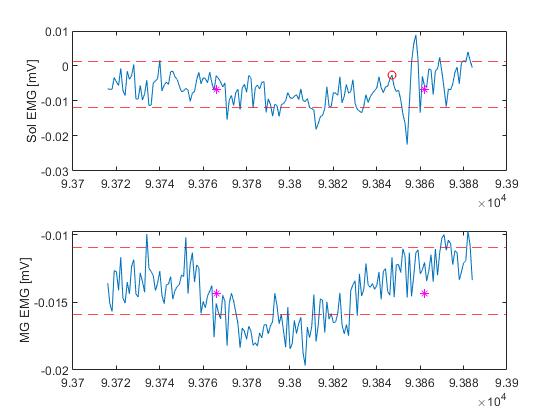

Stretch number 31. Velocity = 55.

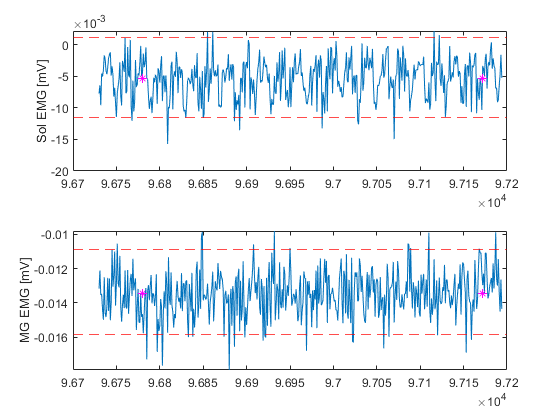

Stretch number 32. Velocity = 110.

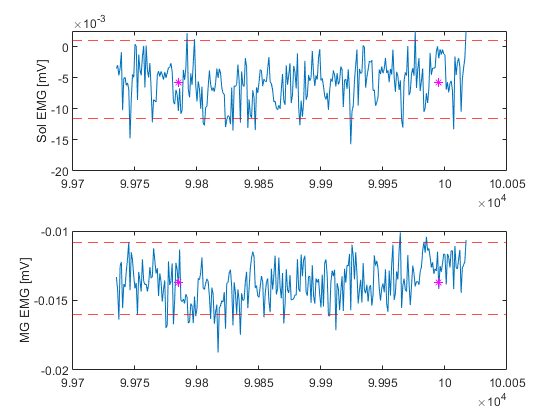

Stretch number 33. Velocity = 211.

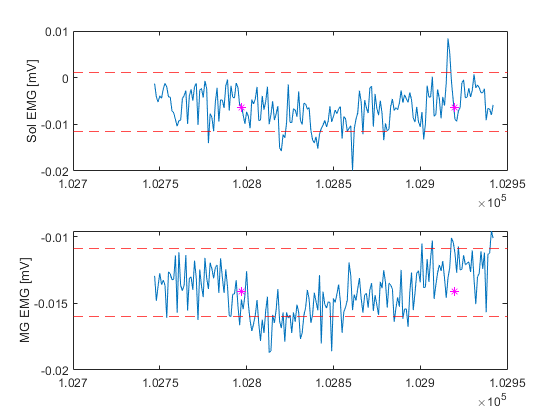

Stretch number 34. Velocity = 294.

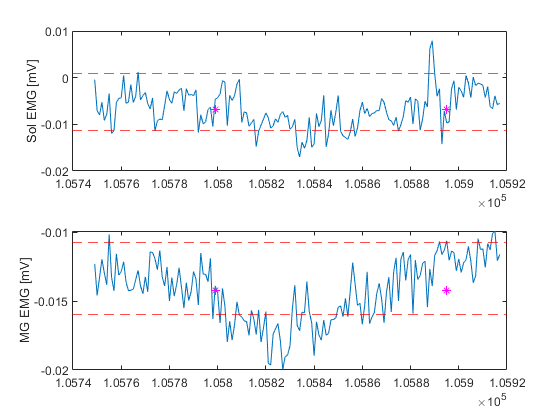

Stretch number 35. Velocity = 55.

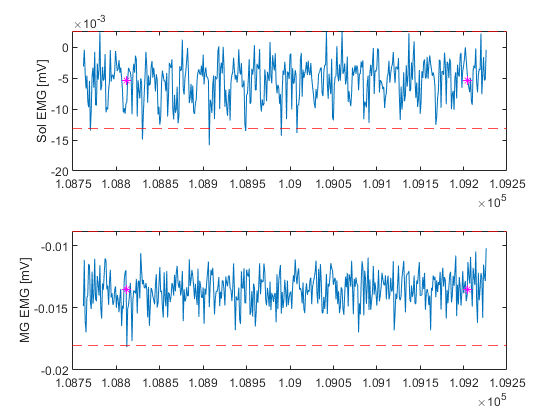

Stretch number 36. Velocity = 109.

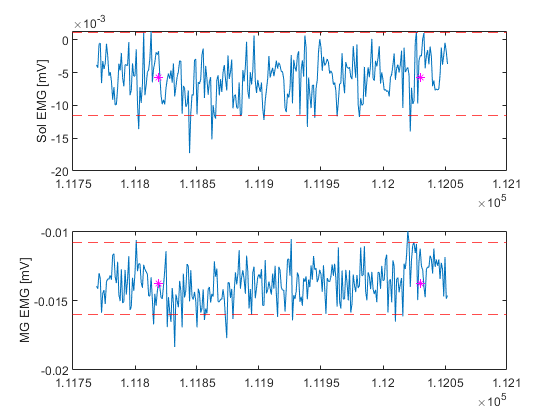

Stretch number 37. Velocity = 55.

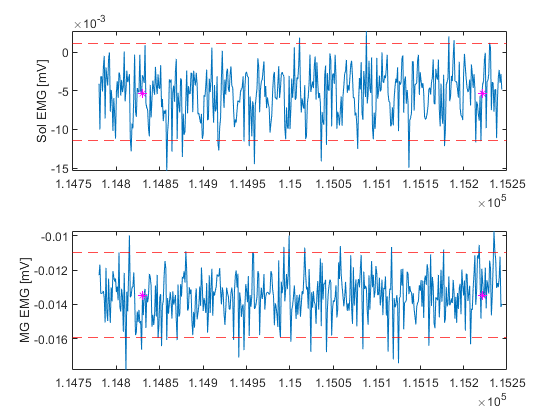

Stretch number 38. Velocity = 110.

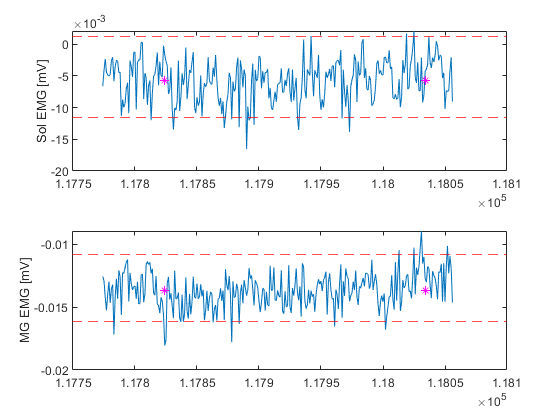

Stretch number 39. Velocity = 213.

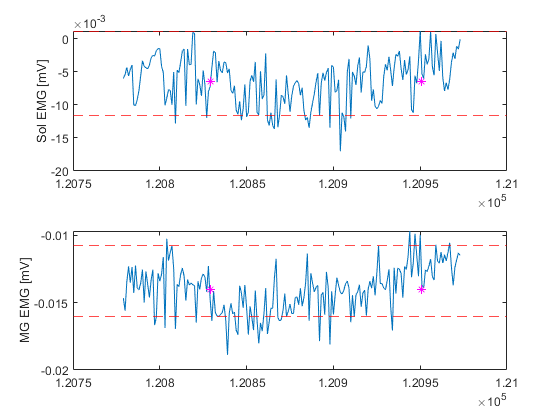

Stretch number 40. Velocity = 294.

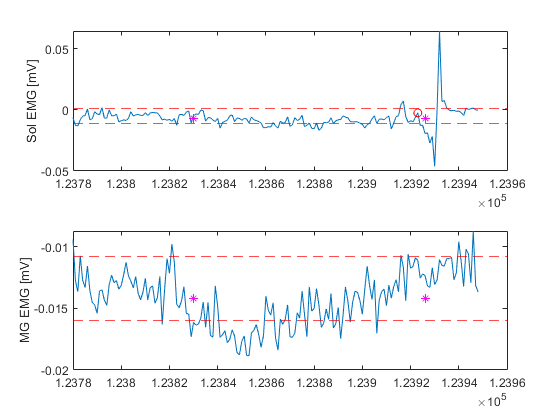

sample_v = [1:length(channel3_d2)]';
for ty = 1:40 %loop to create separate figs for each stretch
    fprintf('Stretch number %i. Velocity = %.0f.',ty,dorsiflex_vel_c(ty));
    figure(ty) 
    subplot(2,1,1) %soleus
    plot(sample_v(index_ev3(ty)-50:index_ev4(ty)+50),channel3_d2(index_ev3(ty)-50:index_ev4(ty)+50))
    ylabel('Sol EMG [mV]')
    if cond_mvc_sol(ty) == 0
        title('higher than 5 percent of the MVC')
    end
    hold on
    if events_emg_sol_sel2(ty) ~= 0
        plot(events_emg_sol_sel2(ty),channel3_d2(events_emg_sol_sel2(ty)),'ro') %_new        
    end
    plot (index_ev3(ty),mean(channel3_d2(index_ev3(ty)-50:index_ev4(ty)+50)),'m*')% references of stretch on EMG signal to facilitate checking FN/FP
    plot (index_ev4(ty)+latency_correction_sol,mean(channel3_d2(index_ev3(ty)-50:index_ev4(ty)+50)),'m*')% end of the stretch + sol latency 
    %new horizontal lines mean+/-2SD based on 500ms before each stretch
    h = yline(mean_emg_interval_plantar_sol1(ty)+std_emg_interval_plantar_sol1(ty)*2, 'r--');
    h2 = yline(mean_emg_interval_plantar_sol1(ty)-std_emg_interval_plantar_sol1(ty)*2, 'r--');
    hold off
    subplot(2,1,2) %m. gastrocnemius
    plot(sample_v(index_ev3(ty)-50:index_ev4(ty)+50),channel4_d2(index_ev3(ty)-50:index_ev4(ty)+50))
    ylabel('MG EMG [mV]')
    if cond_mvc_mg(ty) == 0
        title('higher than 5 percent of the MVC')
    end
    hold on
    if events_emg_mg_sel2(ty) ~= 0
        plot(events_emg_mg_sel2(ty),channel4_d2(events_emg_mg_sel2(ty)),'ro') %_new
    end
    plot (index_ev3(ty),mean(channel4_d2(index_ev3(ty)-50:index_ev4(ty)+50)),'m*')
    plot (index_ev4(ty)+latency_correction_sol,mean(channel4_d2(index_ev3(ty)-50:index_ev4(ty)+50)),'m*')
    %new horizontal lines mean+/-2SD based on 500ms before each stretch
    hh = yline(mean_emg_interval_plantar_mg1(ty)+std_emg_interval_plantar_mg1(ty)*2, 'r--');
    hh2 = yline(mean_emg_interval_plantar_mg1(ty)-std_emg_interval_plantar_mg1(ty)*2, 'r--');
    hold off
end

close all

## Torque/work/angles classified wrt stretch velocities

prestretch_torque_offset = mean(channel1_scaled_window([index_ev1(1)-200:index_ev1(1)])); %average from the last 200 samples before the first stretch
for ii = 1:length(index_ev1)
    prestretch_torque_offset_ev1(ii) = mean(channel1_scaled_window([index_ev1(ii)-200:index_ev1(ii)])); %average from the last 200 samples before the first stretch
    prestretch_torque_offset_ev3(ii) = mean(channel1_scaled_window([index_ev3(ii)-900:index_ev3(ii)-100])); %(ev3-900:ev3-100) --> for avoiding initial movement artefact of the torque channel 
end

aa=1;bb=1;cc=1;dd=1;
%common angle (write here interval)
L1a=3.5;
L2a=16;
for ii = 1:length(index_ev1)
    if dorsiflex_vel(ii)<0.06 %50deg/s
       angles_of_catch_sol_50(aa)=angles_of_catch_sol2(ii);
       angles_of_catch_mg_50(aa)=angles_of_catch_mg2(ii);
       angles_of_catch_sol_50_latency(aa)=angles_of_catch_sol_latency2(ii);
       angles_of_catch_mg_50_latency(aa)=angles_of_catch_mg_latency2(ii);
       %common angle (in deg), 20ms per deg
       interv_torque_com50_L1 = index_ev3(ii)+ L1a*0.02*f_sample_ch1;
       interv_torque_com50_L2 = index_ev4(ii) - (20-L2a)*0.02*f_sample_ch1;
       torque_interval_com50 = channel1_scaled_window(int32(interv_torque_com50_L1):int32(interv_torque_com50_L2));
       delta_torque_com50(aa) = channel1_scaled_window(int32(interv_torque_com50_L2)) - channel1_scaled_window(int32(interv_torque_com50_L1));
       %max_torque_com50(aa) = max(torque_interval_com50)-prestretch_torque_offset; %%OFFSET ADDED!      
       max_torque_com50_ev1(aa) = max(torque_interval_com50)-prestretch_torque_offset_ev1(ii); %%OFFSET ADDED!
       max_torque_com50_ev3(aa) = max(torque_interval_com50)-prestretch_torque_offset_ev3(ii); %%OFFSET ADDED!
       work_com50_ev3(aa) = (trapz(torque_interval_com50-prestretch_torque_offset_ev3(ii)))/1000; % /1000 for time conversion (ms-->s)
       max_work_com50 = max(work_com50_ev3);
       aa=aa+1;
    elseif dorsiflex_vel(ii)<0.12 %100deg
       angles_of_catch_sol_100(bb)=angles_of_catch_sol2(ii);
       angles_of_catch_mg_100(bb)=angles_of_catch_mg2(ii);
       angles_of_catch_sol_100_latency(bb)=angles_of_catch_sol_latency2(ii);
       angles_of_catch_mg_100_latency(bb)=angles_of_catch_mg_latency2(ii); 
       %common angle (in deg), 10ms per deg
       interv_torque_com100_L1 = index_ev3(ii)+ L1a*0.01*f_sample_ch1;
       interv_torque_com100_L2 = index_ev4(ii)- (20-L2a)*0.01*f_sample_ch1;
       torque_interval_com100 = channel1_scaled_window(int32(interv_torque_com100_L1):int32(interv_torque_com100_L2));
       delta_torque_com100(bb) = channel1_scaled_window(int32(interv_torque_com100_L2)) - channel1_scaled_window(int32(interv_torque_com100_L1));
       max_torque_com100_ev1(bb) = max(torque_interval_com100)-prestretch_torque_offset_ev1(ii);
       max_torque_com100_ev3(bb) = max(torque_interval_com100)-prestretch_torque_offset_ev3(ii);
       work_com100_ev3(bb) = (trapz(torque_interval_com100-prestretch_torque_offset_ev3(ii)))/1000; % /1000 for time conversion (ms-->s)
       max_work_com100 = max(work_com100_ev3);
       bb=bb+1;
    elseif dorsiflex_vel(ii)<0.23 %200deg/s
       angles_of_catch_sol_200(cc)=angles_of_catch_sol2(ii);
       angles_of_catch_mg_200(cc)=angles_of_catch_mg2(ii);
       angles_of_catch_sol_200_latency(cc)=angles_of_catch_sol_latency2(ii);
       angles_of_catch_mg_200_latency(cc)=angles_of_catch_mg_latency2(ii);
       cc=cc+1;
    else
       angles_of_catch_sol_270(dd)=angles_of_catch_sol2(ii);
       angles_of_catch_mg_270(dd)=angles_of_catch_mg2(ii);
       angles_of_catch_sol_270_latency(dd)=angles_of_catch_sol_latency2(ii);
       angles_of_catch_mg_270_latency(dd)=angles_of_catch_mg_latency2(ii);
       dd=dd+1;
    end
end
%

## Create vectors for regression (using mvc condition)

Condition for MVC + all the values below a threshold are removed (this helps for possible outliers and for the values=0, which are artificially added for match array-size)

%angles_of_catch_sol2 = angles_of_catch_sol2.*-1;% uncomment for 5217/5218,
%angles_of_catch_mg2 = angles_of_catch_mg2.*-1;
m=1;n=1;
for i=1:length(angles_of_catch_sol2)
    if angles_of_catch_sol2(i) > 0.01 & cond_mvc_sol(i) == 1 
        angles_of_catch_sol_m_cond_mvc(m)= angles_of_catch_sol2(i);
        angles_of_catch_sol_latency_m_cond_mvc(m)= angles_of_catch_sol_latency2(i);
        dorsiflex_vel_c_m_cond_mvc(m)= dorsiflex_vel_c(i);
        m=m+1;
    else
        angles_of_catch_sol_m_cond_mvc(m)= 0;
        angles_of_catch_sol_latency_m_cond_mvc(m)= 0;
        dorsiflex_vel_c_m_cond_mvc(m)= 0;
        m=m+1;
    end
    
    if angles_of_catch_mg2(i) > 0.01 & cond_mvc_mg(i) == 1 
        angles_of_catch_mg_n_cond_mvc(n)= angles_of_catch_mg2(i);
        angles_of_catch_mg_latency_n_cond_mvc(n)= angles_of_catch_mg_latency2(i);
        dorsiflex_vel_c_n_cond_mvc(n)= dorsiflex_vel_c(i);
        n=n+1;
    else
        angles_of_catch_mg_n_cond_mvc(n)= 0;
        angles_of_catch_mg_latency_n_cond_mvc(n)= 0;
        dorsiflex_vel_c_n_cond_mvc(n)= 0;
        n=n+1;
    end
end
angles_of_catch_sol_m_cond_mvc_nonzero = angles_of_catch_sol_m_cond_mvc(angles_of_catch_sol_m_cond_mvc~=0);%vector without zeros for regression
angles_of_catch_sol_latency_m_cond_mvc_nonzero = angles_of_catch_sol_latency_m_cond_mvc(angles_of_catch_sol_latency_m_cond_mvc~=0);%vector without zeros for regression
dorsiflex_vel_c_m_cond_mvc_nonzero = dorsiflex_vel_c_m_cond_mvc(dorsiflex_vel_c_m_cond_mvc~=0);

%swap x and y
%SOL
if num_trials_sol_excluded < 40 %conditions to avoid errors if all the trials are excluded
    p_sol_sw_cond_mvc = polyfit(dorsiflex_vel_c_m_cond_mvc_nonzero,double(angles_of_catch_sol_m_cond_mvc_nonzero),1);
    y1_sol_sw_cond_mvc = polyval(p_sol_sw_cond_mvc,dorsiflex_vel_c_m_cond_mvc_nonzero);
    p_sol_lat_sw_cond_mvc = polyfit(dorsiflex_vel_c_m_cond_mvc_nonzero,double(angles_of_catch_sol_latency_m_cond_mvc_nonzero),1);
    y1_sol_lat_sw_cond_mvc = polyval(p_sol_lat_sw_cond_mvc,dorsiflex_vel_c_m_cond_mvc_nonzero);

    fprintf('SOL the regression parameters (slope) swapped with cond-mvc is %.4f \n',p_sol_sw_cond_mvc(1))
    fprintf('SOL the regression parameters (y-intercept) swapped with cond-mvc is %.4f \n',p_sol_sw_cond_mvc(2))
    fprintf('SOL latency the regression parameters (slope) swapped with cond-mvc is %.4f \n',p_sol_lat_sw_cond_mvc(1))
    fprintf('SOL latency the regression parameters (y-intercept) swapped with cond-mvc is %.4f \n',p_sol_lat_sw_cond_mvc(2))
    R_sol_cond_mvc = corrcoef(dorsiflex_vel_c_m_cond_mvc_nonzero,double(angles_of_catch_sol_m_cond_mvc_nonzero));
    R_sol_lat_cond_mvc = corrcoef(dorsiflex_vel_c_m_cond_mvc_nonzero,double(angles_of_catch_sol_latency_m_cond_mvc_nonzero));

    if length(R_sol_cond_mvc) > 1
        Rsq_sol_cond_mvc = R_sol_cond_mvc(1,2).^2;
        Rsq_sol_lat_cond_mvc = R_sol_lat_cond_mvc(1,2).^2;
        fprintf('R2 SOL-angle of catch with cond-mvc %.4f \n',Rsq_sol_cond_mvc)
        fprintf('R2 SOL-angle of catch latency with cond-mvc %.4f \n',Rsq_sol_lat_cond_mvc)
    else
        fprintf('R2 SOL can not be calculated since only few data available') 
        Rsq_sol_cond_mvc = 0; %as convention due to few data available
        Rsq_sol_lat_cond_mvc = 0;
    end
end
%MG
angles_of_catch_mg_n_cond_mvc_nonzero = angles_of_catch_mg_n_cond_mvc(angles_of_catch_mg_n_cond_mvc~=0);%vector without zeros for regression
angles_of_catch_mg_latency_n_cond_mvc_nonzero = angles_of_catch_mg_latency_n_cond_mvc(angles_of_catch_mg_latency_n_cond_mvc~=0);%vector without zeros for regression
dorsiflex_vel_c_n_cond_mvc_nonzero = dorsiflex_vel_c_n_cond_mvc(dorsiflex_vel_c_n_cond_mvc~=0);
if num_trials_mg_excluded < 40 %30
    p_mg_sw_cond_mvc = polyfit(dorsiflex_vel_c_n_cond_mvc_nonzero,double(angles_of_catch_mg_n_cond_mvc_nonzero),1);
    y1_mg_sw_cond_mvc = polyval(p_mg_sw_cond_mvc,dorsiflex_vel_c_n_cond_mvc_nonzero);
    p_mg_lat_sw_cond_mvc = polyfit(dorsiflex_vel_c_n_cond_mvc_nonzero,double(angles_of_catch_mg_latency_n_cond_mvc_nonzero),1);
    y1_mg_lat_sw_cond_mvc = polyval(p_mg_lat_sw_cond_mvc,dorsiflex_vel_c_n_cond_mvc_nonzero);

    fprintf('MG the regression parameters (slope) swapped with cond-mvc is %.4f \n',p_mg_sw_cond_mvc(1))
    fprintf('MG the regression parameters (y-intercept) swapped with cond-mvc is %.4f \n',p_mg_sw_cond_mvc(2))
    fprintf('MG latency the regression parameters (slope) swapped with cond-mvc is %.4f \n',p_mg_lat_sw_cond_mvc(1))
    fprintf('MG latency the regression parameters (y-intercept) swapped with cond-mvc is %.4f \n',p_mg_lat_sw_cond_mvc(2))
    R_mg_cond_mvc = corrcoef(dorsiflex_vel_c_n_cond_mvc_nonzero,double(angles_of_catch_mg_n_cond_mvc_nonzero));
    R_mg_lat_cond_mvc = corrcoef(dorsiflex_vel_c_n_cond_mvc_nonzero,double(angles_of_catch_mg_latency_n_cond_mvc_nonzero));
    
    if length(R_mg_cond_mvc) > 1
        Rsq_mg_cond_mvc = R_mg_cond_mvc(1,2).^2;
        Rsq_mg_lat_cond_mvc = R_mg_lat_cond_mvc(1,2).^2;

        fprintf('R2 MG-angle of catch with cond-mvc %.4f \n',Rsq_mg_cond_mvc)
        fprintf('R2 MG-angle of catch latency with cond-mvc %.4f \n',Rsq_mg_lat_cond_mvc)
    else
        fprintf('R2 MG can not be calculated since only few data available') 
    end        
end

## Torque/work/angles classified wrt stretch velocities (using mvc condition)

aa_sol=1;bb_sol=1;cc_sol=1;dd_sol=1;
%common angle (write here interval)
L1a=3.5;
L2a=16;
rom_com50 = zeros(length(index_ev1),2); %pre-allocation
rom_com100 = zeros(length(index_ev1),2); %pre-allocation

for ii = 1:length(index_ev1)
    if dorsiflex_vel(ii)<0.06 & cond_mvc_sol(ii) == 1 %50deg/s and condition on MVC
       angles_of_catch_sol_50_cond_mvc(aa_sol)=angles_of_catch_sol2(ii);
       angles_of_catch_sol_50_latency_cond_mvc(aa_sol)=angles_of_catch_sol_latency2(ii);
       %common angle (in deg), 20ms per deg
       interv_torque_com50_L1_cond_mvc = index_ev3(ii)+ L1a*0.02*f_sample_ch1;
       interv_torque_com50_L2_cond_mvc = index_ev4(ii) - (20-L2a)*0.02*f_sample_ch1;
       torque_interval_com50_cond_mvc = channel1_scaled_window(int32(interv_torque_com50_L1_cond_mvc):int32(interv_torque_com50_L2_cond_mvc));    
       max_torque_com50_ev1_cond_mvc(aa_sol) = max(torque_interval_com50_cond_mvc)-prestretch_torque_offset_ev1(ii); %%OFFSET ADDED!
       max_torque_com50_ev3_cond_mvc(aa_sol) = max(torque_interval_com50_cond_mvc)-prestretch_torque_offset_ev3(ii); %%OFFSET ADDED!
       work_com50_ev3_cond_mvc(aa_sol) = (trapz(torque_interval_com50_cond_mvc-prestretch_torque_offset_ev3(ii)))/1000; % /1000 for time conversion (ms-->s)
       max_work_com50_ev3_cond_mvc = max(work_com50_ev3_cond_mvc);
       aa_sol=aa_sol+1;
       rom_com50(ii,1) = interv_torque_com50_L1_cond_mvc; %first col will have all samples where the common rom starts
       rom_com50(ii,2) = interv_torque_com50_L2_cond_mvc; %second col will have all samples where the common rom ends
    elseif dorsiflex_vel(ii)<0.12 & cond_mvc_sol(ii) == 1 %100deg and condition on MVC
       angles_of_catch_sol_100_cond_mvc(bb_sol)=angles_of_catch_sol2(ii);
       angles_of_catch_sol_100_latency_cond_mvc(bb_sol)=angles_of_catch_sol_latency2(ii);
       %common angle (in deg), 10ms per deg
       interv_torque_com100_L1_cond_mvc = index_ev3(ii)+ L1a*0.01*f_sample_ch1;
       interv_torque_com100_L2_cond_mvc = index_ev4(ii)- (20-L2a)*0.01*f_sample_ch1;
       torque_interval_com100_cond_mvc = channel1_scaled_window(int32(interv_torque_com100_L1_cond_mvc):int32(interv_torque_com100_L2_cond_mvc));
       max_torque_com100_ev1_cond_mvc(bb_sol) = max(torque_interval_com100_cond_mvc)-prestretch_torque_offset_ev1(ii);
       max_torque_com100_ev3_cond_mvc(bb_sol) = max(torque_interval_com100_cond_mvc)-prestretch_torque_offset_ev3(ii);
       work_com100_ev3_cond_mvc(bb_sol) = (trapz(torque_interval_com100_cond_mvc-prestretch_torque_offset_ev3(ii)))/1000; % /1000 for time conversion (ms-->s)
       max_work_com100_ev3_cond_mvc = max(work_com100_ev3_cond_mvc);
       bb_sol=bb_sol+1;
       rom_com100(ii,1) = interv_torque_com100_L1_cond_mvc; %first col will have all samples where the common rom starts
       rom_com100(ii,2) = interv_torque_com100_L2_cond_mvc; %second col will have all samples where the common rom ends
    elseif dorsiflex_vel(ii)<0.23  & cond_mvc_sol(ii) == 1 %200deg/s and condition on MVC
       angles_of_catch_sol_200_cond_mvc(cc_sol)=angles_of_catch_sol2(ii);
       angles_of_catch_sol_200_latency_cond_mvc(cc_sol)=angles_of_catch_sol_latency2(ii);
       cc_sol=cc_sol+1;
    elseif cond_mvc_sol(ii) == 1
       angles_of_catch_sol_270_cond_mvc(dd_sol)=angles_of_catch_sol2(ii);
       angles_of_catch_sol_270_latency_cond_mvc(dd_sol)=angles_of_catch_sol_latency2(ii);
       dd_sol=dd_sol+1; 
    end
end

aa_mg=1;bb_mg=1;cc_mg=1;dd_mg=1;
for ii = 1:length(index_ev1)
    if dorsiflex_vel(ii)<0.06 & cond_mvc_mg(ii) == 1 %50deg/s and condition on MVC
       angles_of_catch_mg_50_cond_mvc(aa_mg)=angles_of_catch_mg2(ii);
       angles_of_catch_mg_50_latency_cond_mvc(aa_mg)=angles_of_catch_mg_latency2(ii);
       aa_mg=aa_mg+1;
    elseif dorsiflex_vel(ii)<0.12 & cond_mvc_mg(ii) == 1 %100deg and condition on MVC
       angles_of_catch_mg_100_cond_mvc(bb_mg)=angles_of_catch_mg2(ii);
       angles_of_catch_mg_100_latency_cond_mvc(bb_mg)=angles_of_catch_mg_latency2(ii);
       bb_mg=bb_mg+1;
    elseif dorsiflex_vel(ii)<0.23  & cond_mvc_mg(ii) == 1 %200deg/s and condition on MVC
       angles_of_catch_mg_200_cond_mvc(cc_mg)=angles_of_catch_mg2(ii);
       angles_of_catch_mg_200_latency_cond_mvc(cc_mg)=angles_of_catch_mg_latency2(ii);
       cc_mg=cc_mg+1;
    elseif cond_mvc_mg(ii) == 1
       angles_of_catch_mg_270_cond_mvc(dd_mg)=angles_of_catch_mg2(ii);
       angles_of_catch_mg_270_latency_cond_mvc(dd_mg)=angles_of_catch_mg_latency2(ii);
       dd_mg=dd_mg+1; 
    end
end

fprintf('the total number of trials excluded for SOL 50deg/s is %.1i \n',aa - aa_sol);
fprintf('the total number of trials excluded for SOL 100deg/s is %.1i \n',bb - bb_sol);
fprintf('the total number of trials excluded for SOL 200deg/s is %.1i \n',cc - cc_sol);
fprintf('the total number of trials excluded for SOL 300deg/s is %.1i \n',dd - dd_sol);
fprintf('the total number of trials excluded for MG 50deg/s is %.1i \n',aa - aa_mg);
fprintf('the total number of trials excluded for MG 100deg/s is %.1i \n',bb - bb_mg);
fprintf('the total number of trials excluded for MG 200deg/s is %.1i \n',cc- cc_mg);
fprintf('the total number of trials excluded for MG 300deg/s is %.1i \n',dd - dd_mg);

## Results 1

Dynamic stretch reflex onsets for both muscles, onset EMG RMS, pre-stretch EMG RMS, pre-stretch EMG RMS/MVC EMG RMS, logical vector if trial was accepted (<5%MVCRMS).

Subject(1:40,1) = Subject;
Group (1:40,1) = Group;
Test (1:40,1) = Test;
Trial = (1:40)';
Velocity = round(dorsiflex_vel_c');
cond_mvc_sol = cond_mvc_sol'; 
cond_mvc_mg = cond_mvc_mg';
DSRT_Sol = angles_of_catch_sol_m_cond_mvc'; %DSRT without latency correction Sol
DSRT_Sol_Lat = angles_of_catch_sol_latency_m_cond_mvc'; %DSRT with latency correction Sol
DSRT_MG = angles_of_catch_mg_n_cond_mvc'; %DSRT without latency correction MG
DSRT_MG_Lat = angles_of_catch_mg_latency_n_cond_mvc';  %DSRT with latency correction MG
Pre_emg_Sol = maxs_emgrms_interval_plantar_sol_mw'; %max RMS EMG among stretches, 500ms before the stretch Sol
Pre_emg_MG = maxs_emgrms_interval_plantar_mg_mw'; %max RMS EMG among stretches, 500ms before the stretch Sol
MVC_ratio_Sol = Pre_emg_Sol./emgrms_mvc_sol; %pre-stretch RMS percentage of MVC RMS Sol
MVC_ratio_MG = Pre_emg_MG./emgrms_mvc_mg; %pre-stretch RMS percentage of MVC RMS MG
Onset_emg_Sol = emgrms_onset_sol_new'; %stretch reflex burst 50ms RMS
Onset_emg_MG = emgrms_onset_mg_new'; %stretch reflex burst 50ms RMS
TSRT_main = table(Subject,Group,Test,Trial, Velocity,DSRT_Sol, DSRT_Sol_Lat,DSRT_MG,DSRT_MG_Lat, Onset_emg_Sol,Onset_emg_MG,...
  Pre_emg_Sol,Pre_emg_MG, MVC_ratio_Sol,MVC_ratio_MG,cond_mvc_sol,cond_mvc_mg)

## Results 2

R2, slope and intercept using all or valid trials, for both muscles, with and without latency correction.

Subject = Subject (1);
Group = Group (1);
Test = Test (1);
TSRT_regression = table(Subject, Group,Test, p_sol_sw_cond_mvc, p_sol_lat_sw_cond_mvc, p_mg_sw_cond_mvc,p_mg_lat_sw_cond_mvc,...
Rsq_sol_cond_mvc, Rsq_sol_lat_cond_mvc, Rsq_mg_cond_mvc, Rsq_mg_lat_cond_mvc)

## Results 3

Peak torque and energy calculated in the stretches at 50 and 100 deg/s. Torque offset was subtracted at 20 deg of PF (index_ev3).

Subject(1:10,1) = Subject;
Group (1:10,1) = Group;
Test (1:10,1) = Test;
Trial = (1:10)';
PeakTorque_50 = max_torque_com50_ev3'; 
PeakTorque_100 = max_torque_com100_ev3';
TotalEnergy_50 = work_com50_ev3'; 
TotalEnergy_100 = work_com100_ev3'; 
TSRT_mechanics = table(Subject,Group,Test,Trial,PeakTorque_50, PeakTorque_100, TotalEnergy_50, TotalEnergy_100)
Subject = string(fileName(1:4));
%save(Subject,'TSRT_main','TSRT_regression','TSRT_mechanics')

## FIGURES

figure(1)
subplot(3,1,1)
plot(angle_data) 
ylabel('angles [deg]') 
hold on
plot (index_ev1,angle_data(2),'r.') %0 angle_data(2)==>0
plot (index_ev2,max(angle_data),'k.')
plot (index_ev3,max(angle_data),'y.') %20
plot (index_ev4,angle_data(2),'g.')%0
plot(events_emg_sol_sel2,angles_of_catch_sol2,'r.')
plot(events_emg_sol_sel2,angles_of_catch_sol_latency2,'g.')
hold off
subplot(3,1,2)
plot(channel3_d2)
title('raw sol EMG')
hold on
plot (index_ev3,0,'m*')
plot (index_ev4,0,'m*') 
%plot(channel3_filt,'g')
ylabel('Sol EMG [mV]')
plot(events_emg_sol_sel2,0,'ro')
plot(events_emg_sol,0,'g.')
hold off
subplot(3,1,3)
plot(channel3_filt,'b') %
title('filtered sol EMG')
hold on
plot(events_emg_sol_sel2,0,'ro')
plot(events_emg_sol,0,'g.')
plot (index_ev3,0,'m*')
plot (index_ev4,0,'m*')
ylabel('Sol EMG [mV]')
xlabel('time [samples]')
%hold on
%plot(emgrms_sol,'g')
hold off
figure(2)
subplot(3,1,1)
plot(angle_data)%_resampled) 
ylabel('Angle [deg]')
hold on
plot (index_ev1,angle_data(2),'r.')
plot (index_ev2,max(angle_data),'k.')
plot (index_ev3,max(angle_data),'y.')
plot (index_ev4,angle_data(2),'g.')
plot(events_emg_sol_sel2,angles_of_catch_sol2,'r.')
plot(events_emg_mg_sel2,angles_of_catch_mg2,'g.')
hold off
subplot(3,1,2)
plot(channel4_d2)
title('raw MG EMG')
ylabel('MG EMG [mV]')
hold on
plot (index_ev3,0,'m*')
plot (index_ev4,0,'m*')
plot(events_emg_mg_sel2,0,'ko')
plot(events_emg_mg,0,'g.')
hold off
subplot(3,1,3)
hold on
plot(channel4_filt,'b')
plot (index_ev3,0,'m*')
plot (index_ev4,0,'m*')
plot(events_emg_mg_sel2,0,'ro')
plot(events_emg_mg,0,'g.')
title('filtered MG EMG')
ylabel('MG EMG [mV]')
xlabel('time [samples]')
hold off
figure(3)
subplot(3,1,1)
hold on
plot(angle_data)%_resampled) 
ylabel('Angle [deg]')
plot (index_ev1,0,'r.')
plot (index_ev2,20,'k.')
plot (index_ev3,20,'y.')
plot (index_ev4,0,'g.')
plot(events_emg_sol_sel2,angles_of_catch_sol2,'r.')
plot(events_emg_mg_sel2,angles_of_catch_mg2,'g.')
%plot(rom_com50(:,1))
for tx=1:40
    jj = xline(rom_com50(tx,1), 'm--');
    jj2 = xline(rom_com50(tx,2), 'm--');
    ww = xline(rom_com100(tx,1), 'k--');
    ww2 = xline(rom_com100(tx,2), 'k--');
end
subplot(3,1,2)
hold on
plot(channel1_scaled)
for tx=1:40
    jj = xline(rom_com50(tx,1), 'm--');
    jj2 = xline(rom_com50(tx,2), 'm--');
    ww = xline(rom_com100(tx,1), 'k--');
    ww2 = xline(rom_com100(tx,2), 'k--');
end
ylabel('raw Ankle Torque [Nm]')
subplot(3,1,3)
hold on
plot(channel1_scaled_window,'r')
plot (index_ev1,channel1_scaled_window(index_ev1),'ro')
plot (index_ev2,channel1_scaled_window(index_ev2),'ko')
plot (index_ev3,channel1_scaled_window(index_ev3),'yo')
plot (index_ev4,channel1_scaled_window(index_ev4),'go')
for tx=1:40
    jj = xline(rom_com50(tx,1), 'm--');
    jj2 = xline(rom_com50(tx,2), 'm--');
    ww = xline(rom_com100(tx,1), 'k--');
    ww2 = xline(rom_com100(tx,2), 'k--');
end
ylabel('filtered Ankle Torque [Nm]')
xlabel('time [samples]')

if num_trials_sol_excluded < 40 
    figure(5)
    hold on
    plot(dorsiflex_vel_c_m_cond_mvc_nonzero,angles_of_catch_sol_m_cond_mvc_nonzero,'go')
    plot(dorsiflex_vel_c_m_cond_mvc_nonzero,y1_sol_sw_cond_mvc,'g')
    plot(dorsiflex_vel_c_m_cond_mvc_nonzero,angles_of_catch_sol_latency_m_cond_mvc_nonzero,'bo')
    plot(dorsiflex_vel_c_m_cond_mvc_nonzero,y1_sol_lat_sw_cond_mvc,'b')
    ylim([0 20])
    xlim([0 300])
    grid on
    ylabel('Angle of catch [deg]')
    xlabel('Ankle velocity [deg/s]')
    title('Soleus - condition MVC')
    legend({'SOL','regression line SOL', 'SOL latency','regression line SOL latency'},'Location','southwest')
end

if num_trials_sol_excluded < 40 
    figure(7)
    hold on
    plot(dorsiflex_vel_c_n_cond_mvc_nonzero,angles_of_catch_mg_n_cond_mvc_nonzero,'ro')
    plot(dorsiflex_vel_c_n_cond_mvc_nonzero,y1_mg_sw_cond_mvc,'r')
    plot(dorsiflex_vel_c_n_cond_mvc_nonzero,angles_of_catch_mg_latency_n_cond_mvc_nonzero,'mo')
    plot(dorsiflex_vel_c_n_cond_mvc_nonzero,y1_mg_lat_sw_cond_mvc,'m')
    ylim([0 20])
    xlim([0 300])
    grid on
    ylabel('Angle of catch [deg]')
    xlabel('Ankle velocity [deg/s]')
    title('Medial Gastro - condition MVC')
    legend({'MG','regression line MG', 'MG latency','regression line MG latency'},'Location','southwest')
end

% figure(10)
% plot(angles_of_catch_sol_50,'ro') 
% hold on
% plot(angles_of_catch_sol_100,'go')
% plot(angles_of_catch_sol_200,'bo')
% plot(angles_of_catch_sol_270,'ko')
% % plot(angles_of_catch_sol_50_latency,'rx')
% % plot(angles_of_catch_sol_100_latency,'gx')
% % plot(angles_of_catch_sol_200_latency,'bx')
% % plot(angles_of_catch_sol_270_latency,'kx')
% ylabel('SOL-onset Angles of catch [deg]')
% xlabel('trials')
% title('all angles detected') % angles=0 MEANS NO STRETCH REFLEX FOUND
% ylim([0 20])
% grid on
% legend({'50 deg/s','100 deg/s', '200 deg/s','300 deg/s'},'Location','southwest')

figure(11)
hold on
plot(angles_of_catch_sol_50_latency,'rx')
plot(angles_of_catch_sol_100_latency,'gx')
plot(angles_of_catch_sol_200_latency,'bx')
plot(angles_of_catch_sol_270_latency,'kx')
ylabel('SOL-onset Angles of catch [deg]')
xlabel('trials')
ylim([0 20])
grid on
legend({'50 deg/s','100 deg/s', '200 deg/s','300 deg/s'},'Location','southwest')
title('SOL - considering LATENCY')

% figure(12)
% plot(angles_of_catch_mg_50,'ro')
% hold on
% plot(angles_of_catch_mg_100,'go')
% plot(angles_of_catch_mg_200,'bo')
% plot(angles_of_catch_mg_270,'ko')
% ylabel('MG-onset Angles of catch [deg]')
% xlabel('trials')
% title('all angles detected') % angles=0 MEANS NO STRETCH REFLEX FOUND
% ylim([0 20])
% grid on
% legend({'50 deg/s','100 deg/s', '200 deg/s','300 deg/s'},'Location','southwest')

figure(13)
hold on
plot(angles_of_catch_mg_50_latency,'rx')
plot(angles_of_catch_mg_100_latency,'gx')
plot(angles_of_catch_mg_200_latency,'bx')
plot(angles_of_catch_mg_270_latency,'kx')
xlabel('trials')
ylabel('MG-onset Angles of catch [deg]')
ylim([0 20])
grid on
legend({'50 deg/s','100 deg/s', '200 deg/s','300 deg/s'},'Location','southwest')
title('MG - considering LATENCY')

figure(13)
hold on
plot(angles_of_catch_mg_50_latency,'rx')
plot(angles_of_catch_mg_100_latency,'gx')
plot(angles_of_catch_mg_200_latency,'bx')
plot(angles_of_catch_mg_270_latency,'kx')
xlabel('trials')
ylabel('MG-onset Angles of catch [deg]')
ylim([0 20])
grid on
legend({'50 deg/s','100 deg/s', '200 deg/s','300 deg/s'},'Location','southwest')
title('MG - considering LATENCY')

figure(15) %peak torque COMMON ROM 2 velocities (50 + 100 deg/s)
%plot(max_torque_com50,'ro')
hold on
%plot(max_torque_com50_ev1,'rx')
plot(max_torque_com50_ev3,'rv')
%plot(max_torque_com100,'go')
%plot(max_torque_com100_ev1,'gx')
plot(max_torque_com100_ev3,'gv')
ylabel('Max Ankle Torque [Nm]')
xlabel('trials')
grid on
title('COMMON-range') 
legend({'50 deg/s ev3','100 deg/s ev3'},'Location','southwest')

figure(16) %torque common ROM without artefacts
plot(work_com50_ev3,'ro')
hold on
plot(work_com100_ev3,'go')
ylabel('Ankle Work [J]')
xlabel('trials')
grid on
title('COMMON-range') 
legend({'50 deg/s','100 deg/s'},'Location','southwest')

figure(17)
plot(maxs_emgrms_interval_plantar_sol_mw,'gx')
hold on
plot(emgrms_onset_sol_new,'go')
plot(maxs_emgrms_interval_plantar_mg_mw,'rx')
plot(emgrms_onset_mg_new,'ro')
ylabel('RMS EMG [mV]')
xlabel('trials')
grid on
legend({'SOL interv','SOL onset','MG interv','MG onset'},'Location','northeast')

% clear variables
clear a a0 a1 b b0 b1 c ciao  L1a L2a i ii j l i7 i8 m mm n ttmg ttsol ty
% Notes
% Adjustments in the 5%MVC threshold needed to be done in some participants, 
% the reasons are slightly increased background noise (constant throught the trial, 
% not muscle activation) or very low MVC RMS values in which even slight changes 
% in background noises can cause the threshold to be reached.
% 
% 5105/5108/5112/5116 -  Threshold was increased to 6.5%.
% 
% 5113 - Threshold was increased to 7%.
% 
% 5106/5112 -  Threshold was increased to 8.5%.
% 
% To check emg pre stretch/MVC EMG:
% 
% maxs_emgrms_interval_plantar_sol_mw./emgrms_mvc_sol
% 
% maxs_emgrms_interval_plantar_mg_mw./emgrms_mvc_mg

#### Notes

Adjustments in the 5%MVC threshold needed to be done in some participants, the reasons are slightly increased background noise (constant throught the trial, not muscle activation) or very low MVC RMS values in which even slight changes in background noises can cause the threshold to be reached. The minimum increase in the threshold that could increase the number of included trials was chosen, 8.5% was the maximum used.

5108/5116/5216/5110/5215 -  Threshold was increased to 6.5%.

5105/5113/5119/5218 - Threshold was increased to 7%.

5106/5112 -  Threshold was increased to 8.5%.

5216 has clear electrical spikes in some trials, they were discarded. 

5217 has emg onset very close to neutral position, the vars angles_of_catch_sol2 and mg2 have to be multiplied by -1 (a small shift in offset turned the values slightly negative. Additionally, the conditions at lines 867/879 have to be changed to >0 to perform the regression analysis. 

To check emg pre stretch/MVC EMG:

maxs_emgrms_interval_plantar_sol_mw./emgrms_mvc_sol

maxs_emgrms_interval_plantar_mg_mw./emgrms_mvc_mg